# create DataSet objects

clc;
warning("off","all");

% make data object
[obj_arr, mset_arr] = make_objs();

% select dataset to analyze
% 1 = CO2, 2 = CH4, 3 = d18O
epica_data = obj_arr{3}; 

# set Y, M & create cross-dataset time range

% create global time range for which all three objects can be interpolated!
lower_bound = max( [ min(obj_arr{1}.X), min(obj_arr{2}.X), min(obj_arr{3}.X) ]);
upper_bound = min( [ max(obj_arr{1}.X), max(obj_arr{2}.X), max(obj_arr{3}.X) ]);

data_range = upper_bound - lower_bound;
freq = 4.25 * 10^(-5);
per = 1/freq;

Y = round(data_range / per);     % 34
M = 50;

global xx;
xx = linspace(lower_bound,upper_bound,Y*M);

# plot time series

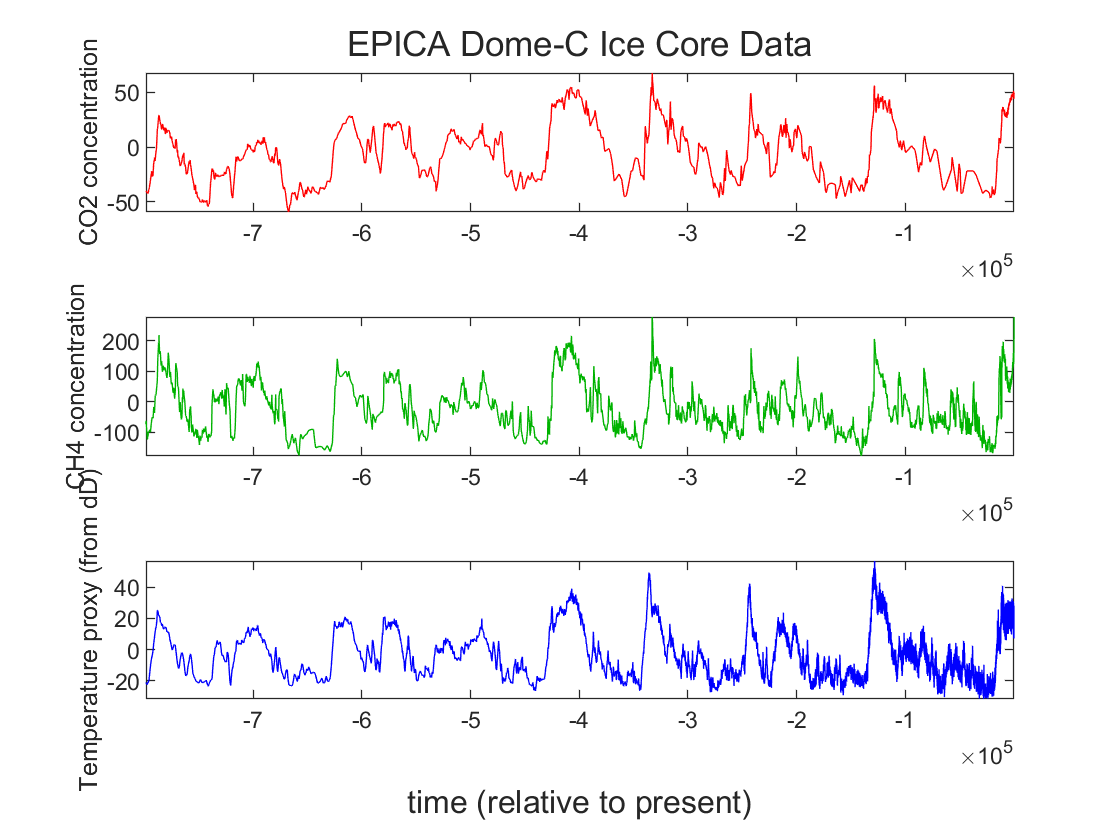

close all;

t = tiledlayout(3,1);

colors = [ [1,0,0]; [0,0.7,0]; [0,0,1] ];
yl = ["CO2 concentration","CH4 concentration","Temperature proxy (from dD)"];

for i=1:3
    oi = obj_arr{i};
    nexttile
    plot(oi.X,oi.Y - oi.data_mean,'Color',colors(i,:));
    xlim([lower_bound,upper_bound]);
    ylabel(yl(i));
end
title(t,"EPICA Dome-C Ice Core Data");
xlabel(t,"time (relative to present)");

# plot power spectra of datasets

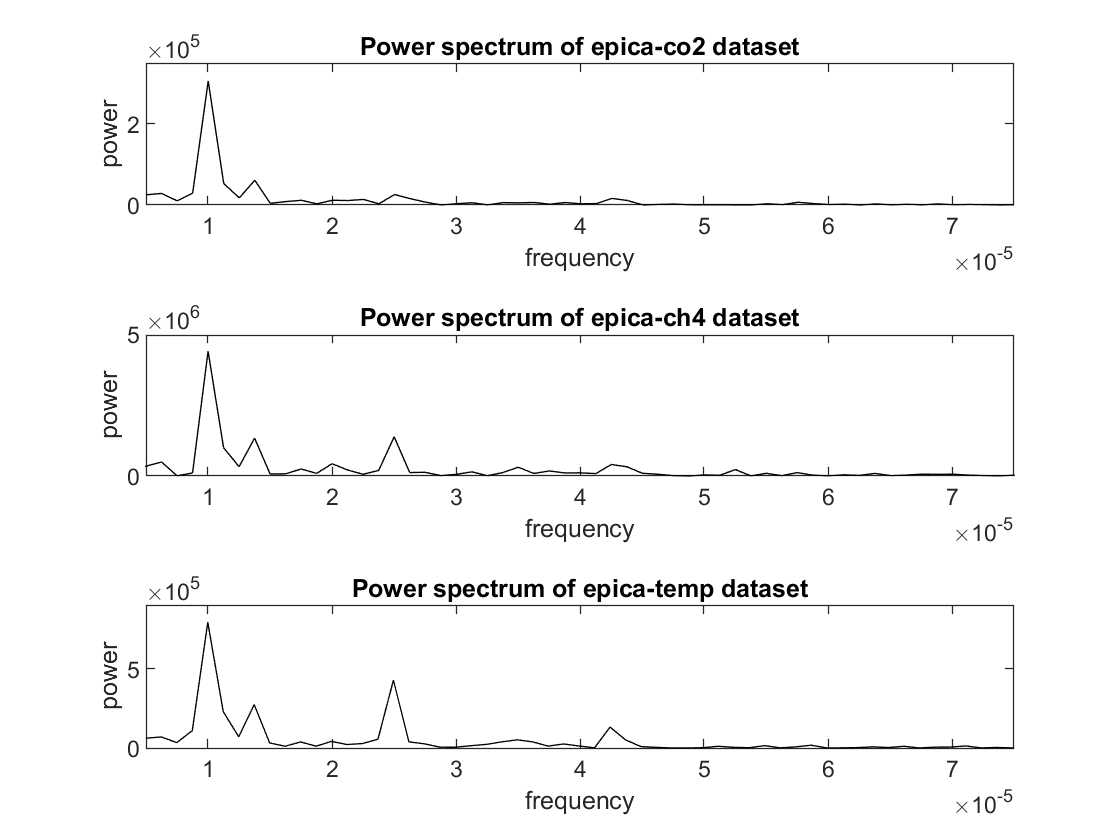

close all;

tiledlayout(3,1);

nexttile
power_spectrum(obj_arr{1});
xlim([0.000005 0.000075])
ylim([0 350000])

nexttile
power_spectrum(obj_arr{2});
xlim([0.000005 0.000075])
ylim([0 5000000])

nexttile
power_spectrum(obj_arr{3});
xlim([0.000005 0.000075])
ylim([0 900000])

# find 1D model parameters a, N, f

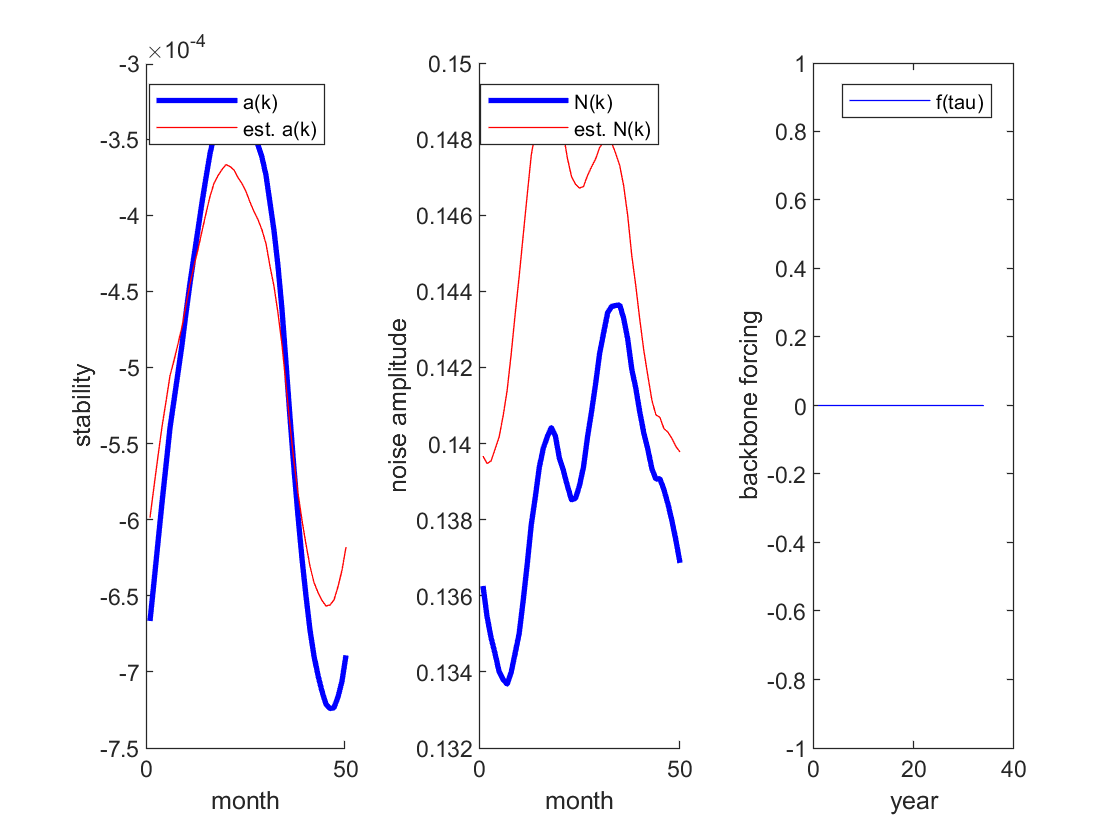

close all;

% full complex findanf
model_params = findanf_epica(epica_data,Y,M,'mm',10,'br_win',M/2);
a_final = model_params{1,:};
N = model_params{2,:};
f = model_params{3,:};

% Woosok estimate version
anf_est1D = findanf_epica(epica_data,Y,M,'est',1,'br_win',M/2);
a_est = anf_est1D{1,:};
N_est = anf_est1D{2,:};

t = tiledlayout(1,3);

% plot a-values in fig. 1
nexttile
hold on;
plot(a_final,'LineWidth',2,'Color','blue');
plot(a_est,'Color','red');
xlabel("month");
ylabel("stability");
%title(sprintf("a(k) for %s, Y=%d M=%d",epica_data.data_name, Y, M));
legend("a(k)","est. a(k)");
saveas(gcf,sprintf("%s_a_%d-%d.jpeg",epica_data.data_name,Y,M));

% plot N-values in fig. 2
nexttile
hold on;
plot(N,'LineWidth',2,'Color','blue');
plot(N_est,'Color','red');
xlabel("month");
ylabel("noise amplitude");
%title(sprintf("N(k) for %s, Y=%d M=%d",epica_data.data_name, Y, M));
legend("N(k)","est. N(k)");
saveas(gcf,sprintf("%s_N_%d-%d.jpeg",epica_data.data_name,Y,M));

% plot f-values in fig. 3
nexttile
plot(f,'Color','blue');
xlabel("year");
ylabel("backbone forcing");
%title(sprintf("f(tau) for %s, Y=%d M=%d",epica_data.data_name,Y,M));
legend("f(tau)");
saveas(gcf,sprintf("%s_f_%d-%d.jpeg",epica_data.data_name,Y,M));

# estimate response timescale & year offset m for B(k)

% get 'month' length in (actual) years
M_length = range(epica_data.X) / (Y*M);

% "integrate" (sum up) estimated a(k), divide by 'month' length
int_aest = sum(a_est) / M_length;

% get response timescale
T_a = 1 / abs(int_aest);

% convert response timescale to number of 'month's and 'year's
num_M_est = T_a / M_length;
num_Y_est = num_M_est / M;

% get final rounded estimate (in years) for response timescale
T_final = round(num_Y_est)

T_final = 1

# plot intermediate model quantities

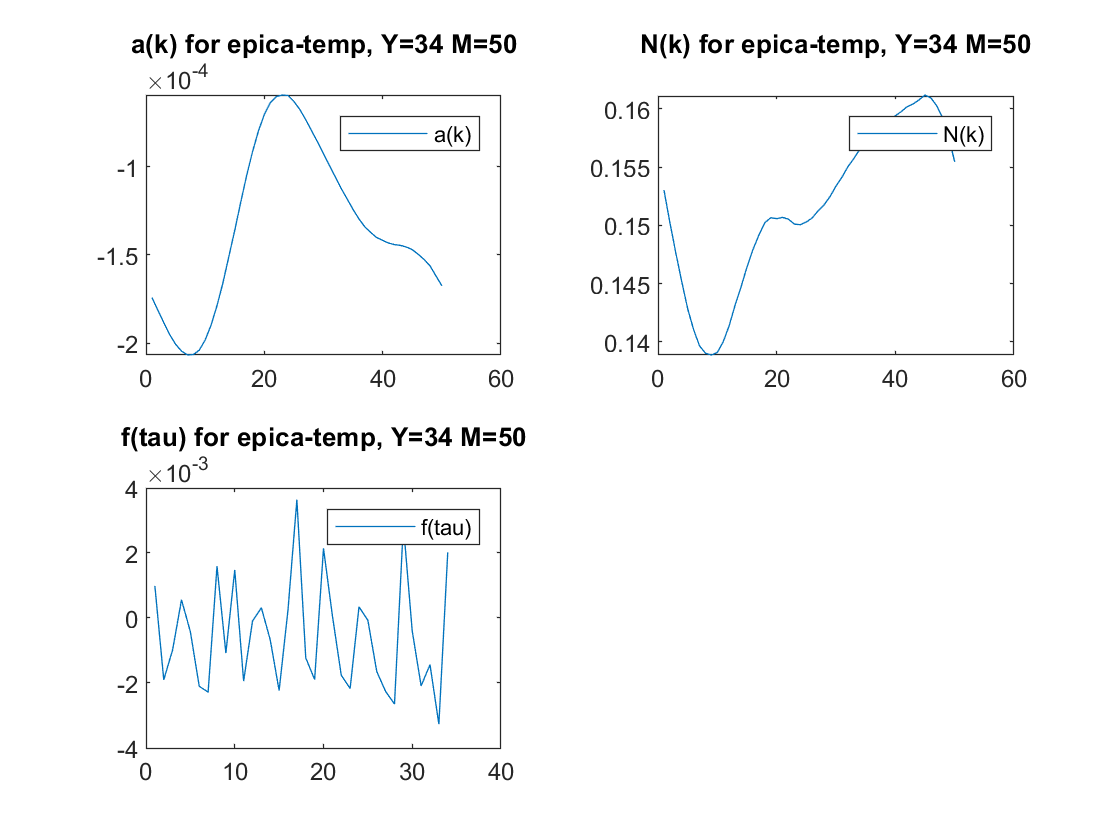

findanf_epica(epica_data,Y,M,'mm',5,'plt',1,'br_win',0);

# 1D non-br model

### calculate & simulate

close all;

br_win = 0;
est = 0;
m = min( int16((T_final + Y) / 2), Y-4 )

m = int16
18

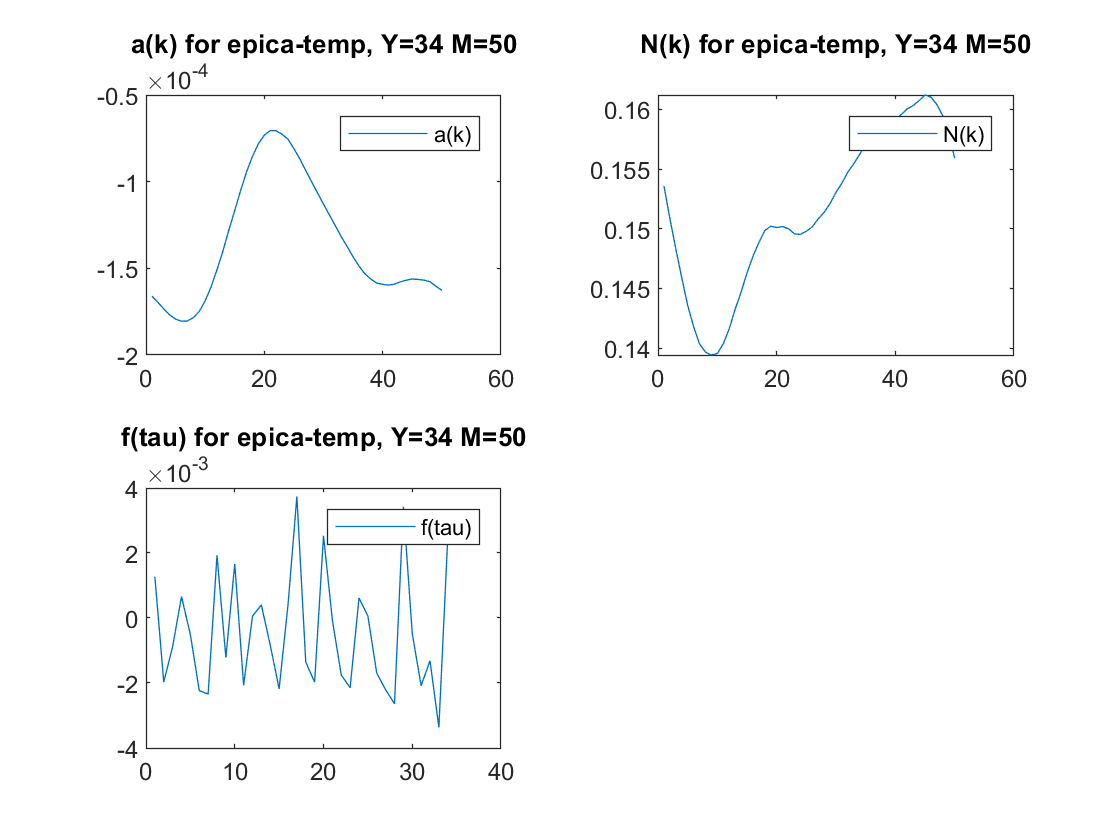

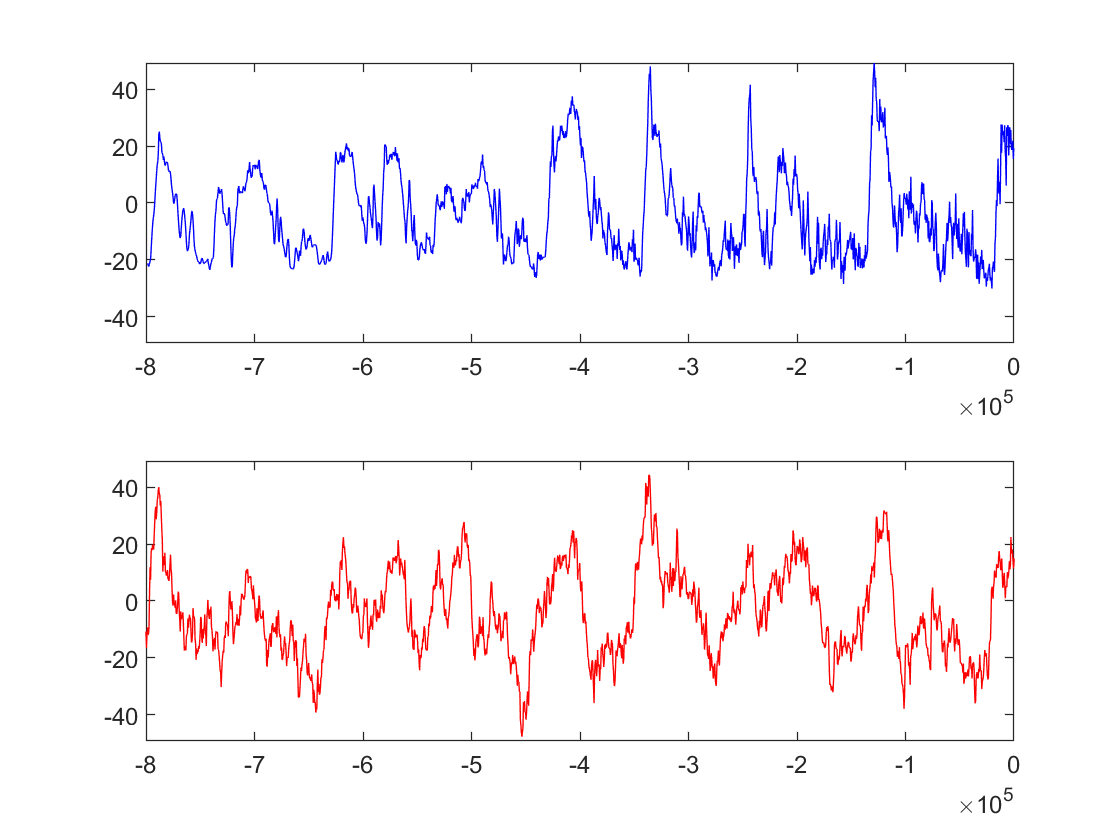


anf_nonbr1D = findanf_epica(epica_data,Y,M,'mm',m,'est',est,'br_win',br_win,'plt',1);

[sim_x_nonbr1D, sim_n_nonbr1D] = epica_sim1D(epica_data,Y,M,anf_nonbr1D,br_win,1);

### **compare PDFs**

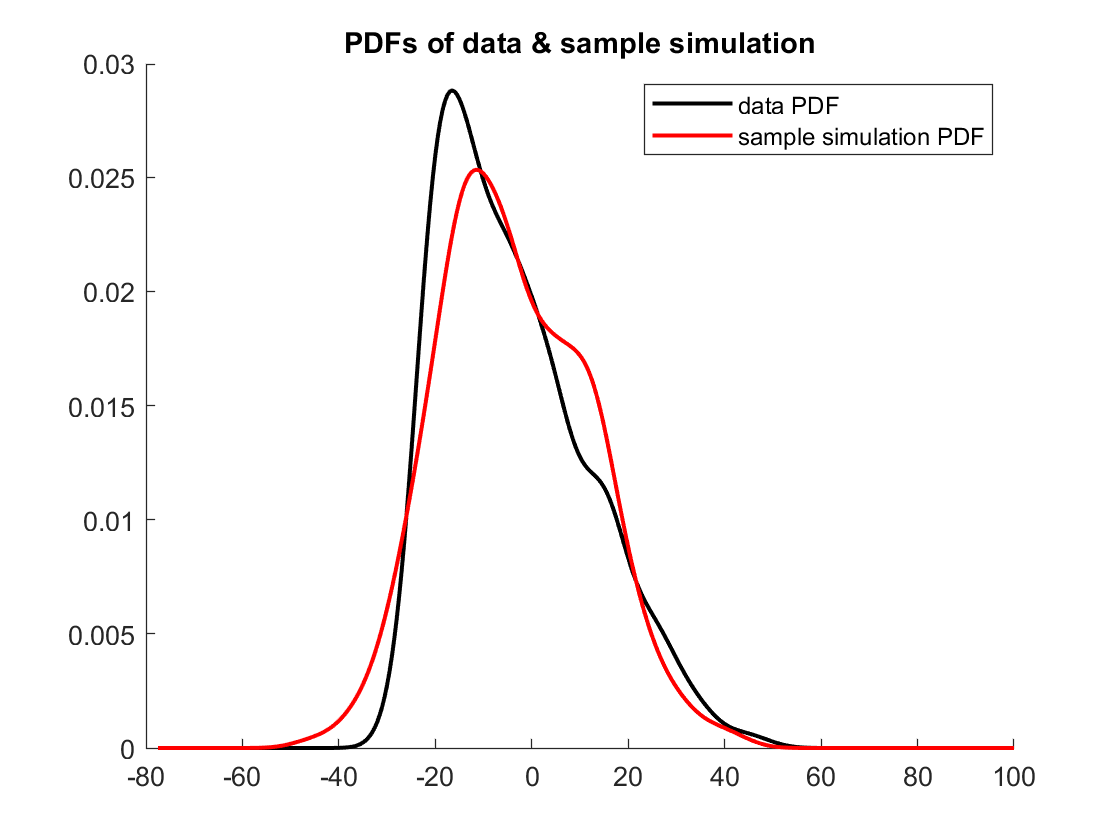

	data summary stats	avgsim summary stats
mean:		-3.730			-8.521
std:		15.222			23.176
skew:		0.738			1.264


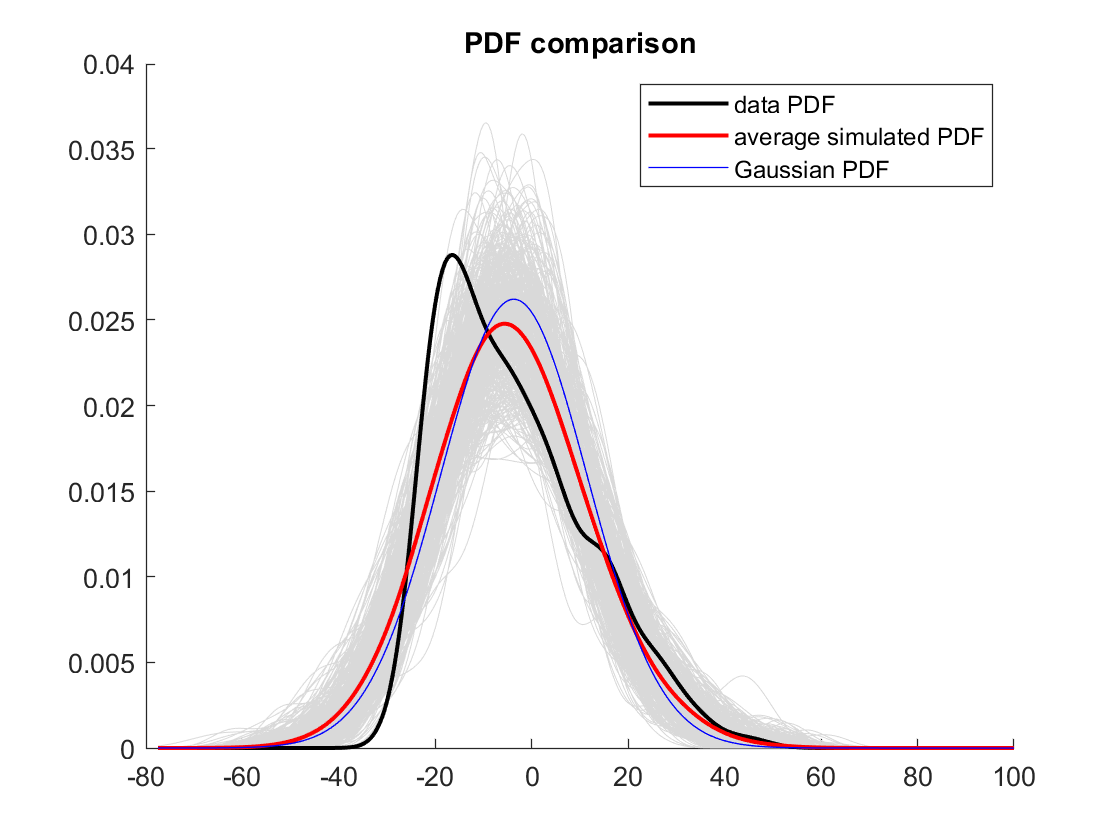

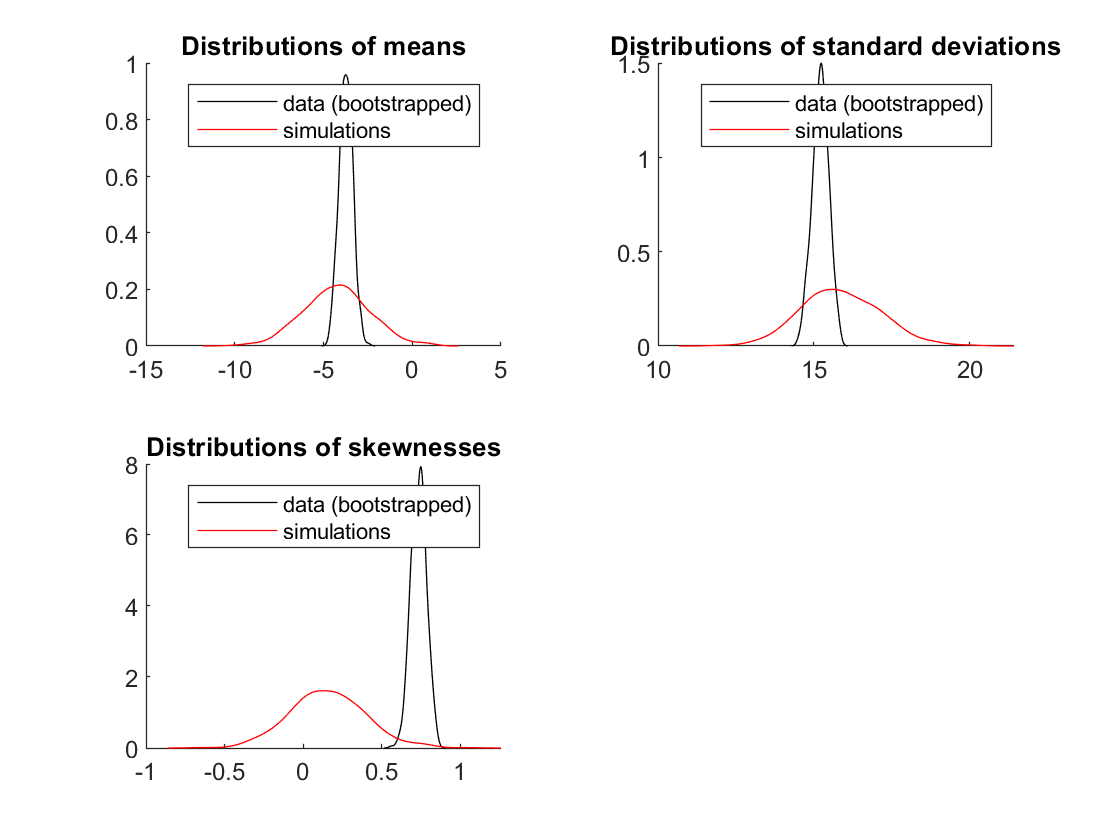

modelpdf_1D(epica_data,Y,M,sim_n_nonbr1D,0);

### compare MFTWDFA

[matrix_x,matrix_y,~] = data2matrix(epica_data,Y,M,0);
data_x_nonbr1D = reshape(matrix_x',[],1);
data_y_nonbr1D = reshape(matrix_y',[],1);

data_obj_nonbr1D = DataSet("vbl","noise-data",data_x_nonbr1D,data_y_nonbr1D);
sim_obj_nonbr1D = DataSet("vbl","noise-sim",sim_x_nonbr1D,sim_n_nonbr1D);

%{
close all;
% nexttile
hold on;

[t_arr1,f_arr1] = mftwdfa(data_obj_nonbr1D,{"makima",1000,2});
[t_arr2,f_arr2] = mftwdfa(sim_obj_nonbr1D,{"makima",1000,2});

plot(log10(t_arr1),log10(f_arr1),'Color','black');
plot(log10(t_arr2),log10(f_arr2),'Color','red');
xlabel("log(t)");
ylabel("log F_2");
title("Fluctuation function of data and simulation");
legend("data F_2","simulation F_2");
%}

### **compare power spectra**

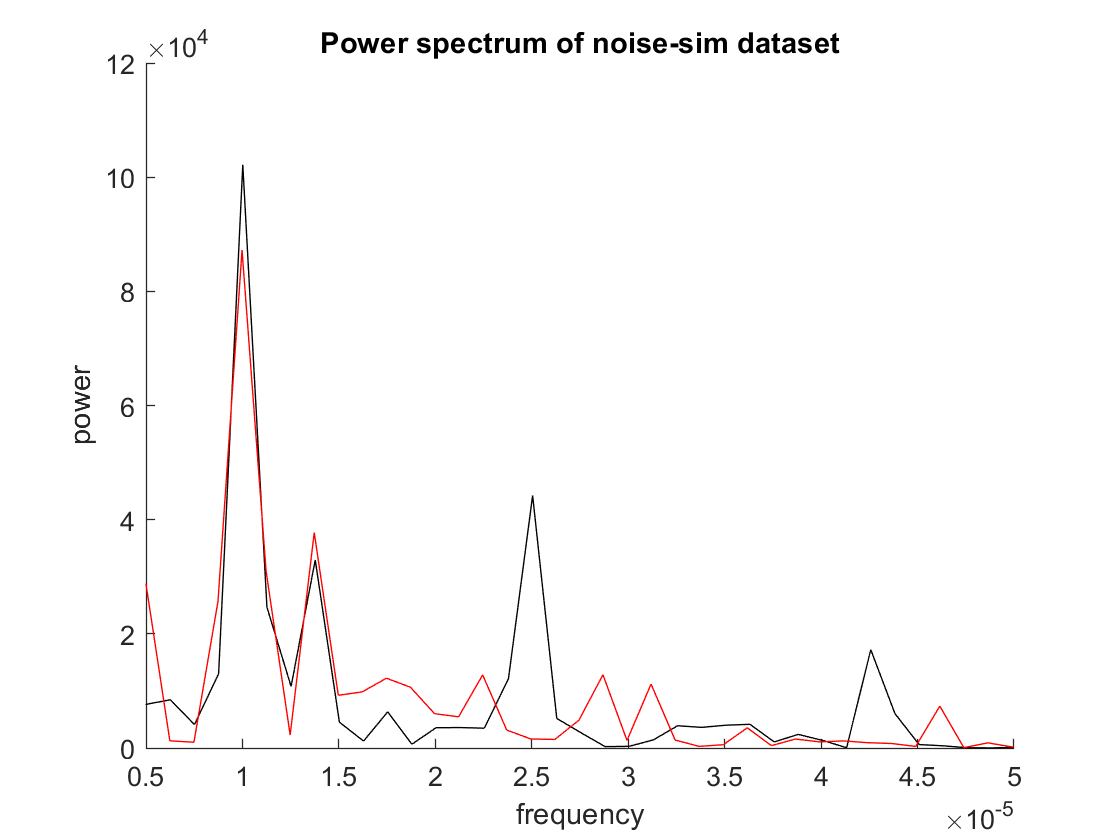

close all;
% nexttile
hold on;
power_spectrum(data_obj_nonbr1D,'black');
power_spectrum(sim_obj_nonbr1D,'red');
xlim([0.000005 0.00005]);

### compare stdev

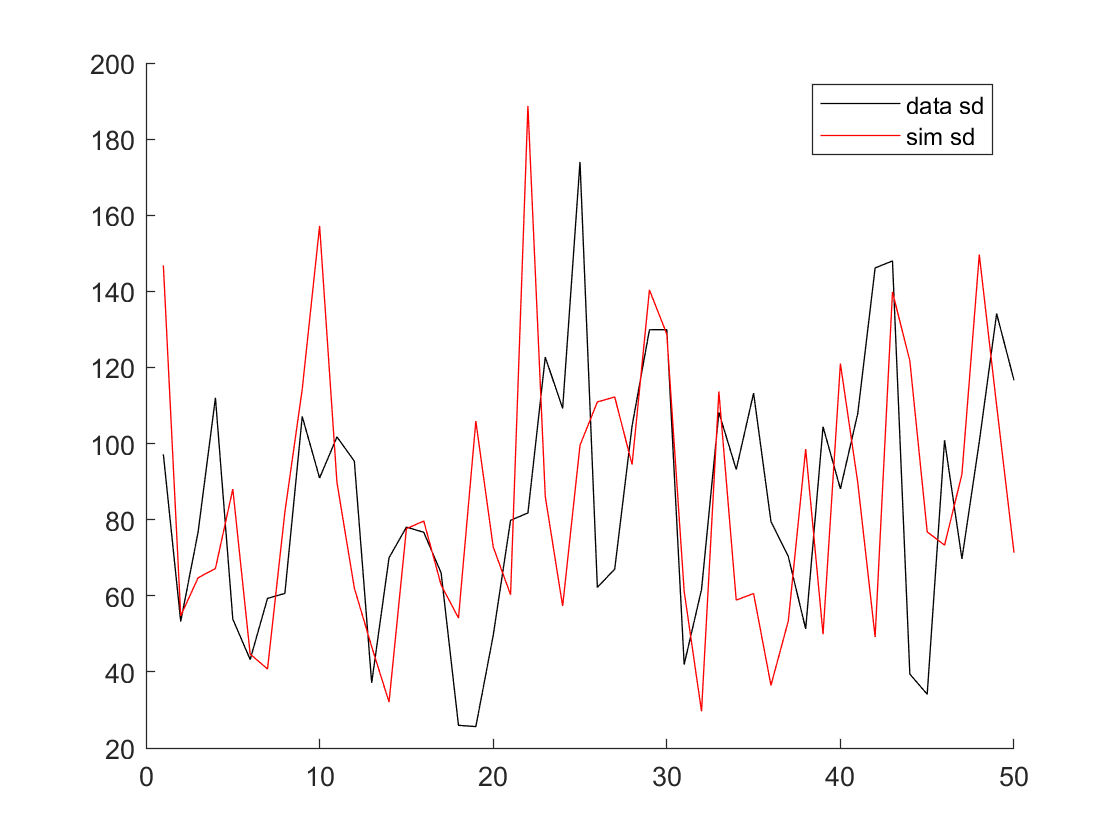

close all;
compare_stdev(data_y_nonbr1D,sim_n_nonbr1D,Y,M);

# 1D br model

### calculate & simulate

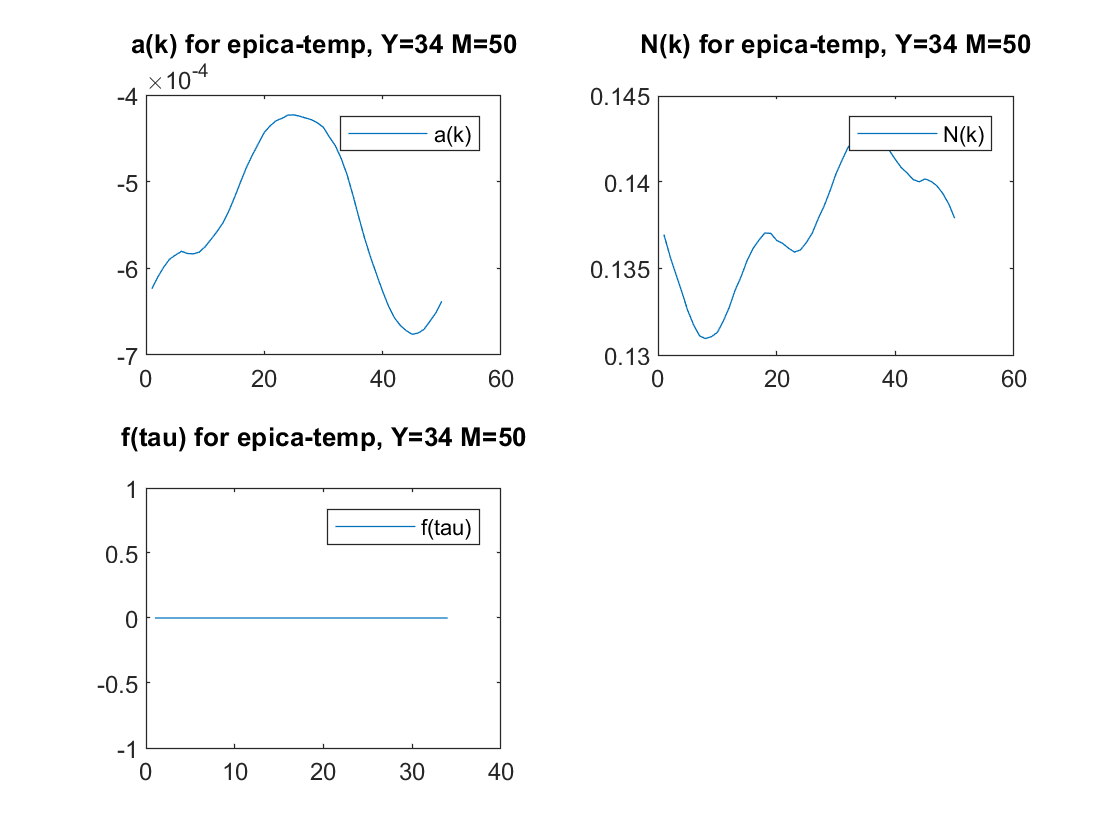

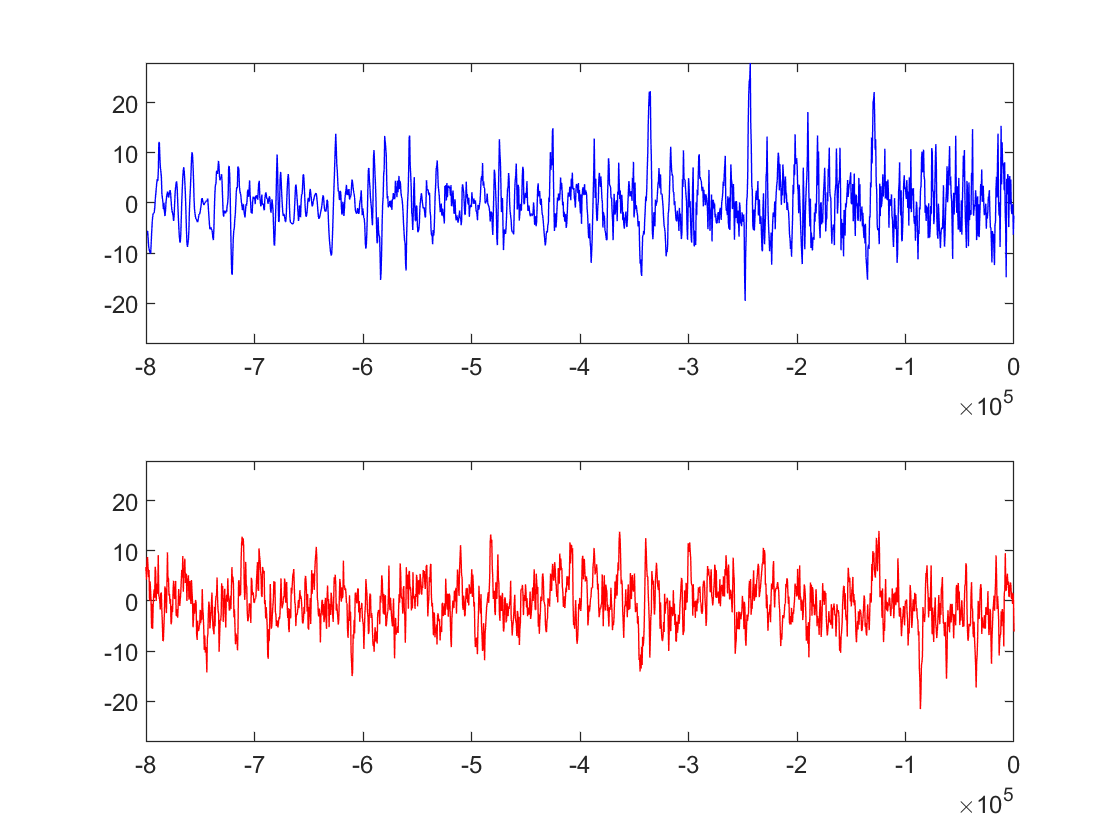

close all;

br_win = floor(M/2);
est = 0;
plt = 1;

anf_br1D = findanf_epica(epica_data,Y,M,'est',est,'br_win',br_win,'plt',plt);
[sim_x_br1D, sim_n_br1D] = epica_sim1D(epica_data,Y,M,anf_br1D,br_win,1);

### compare PDFs

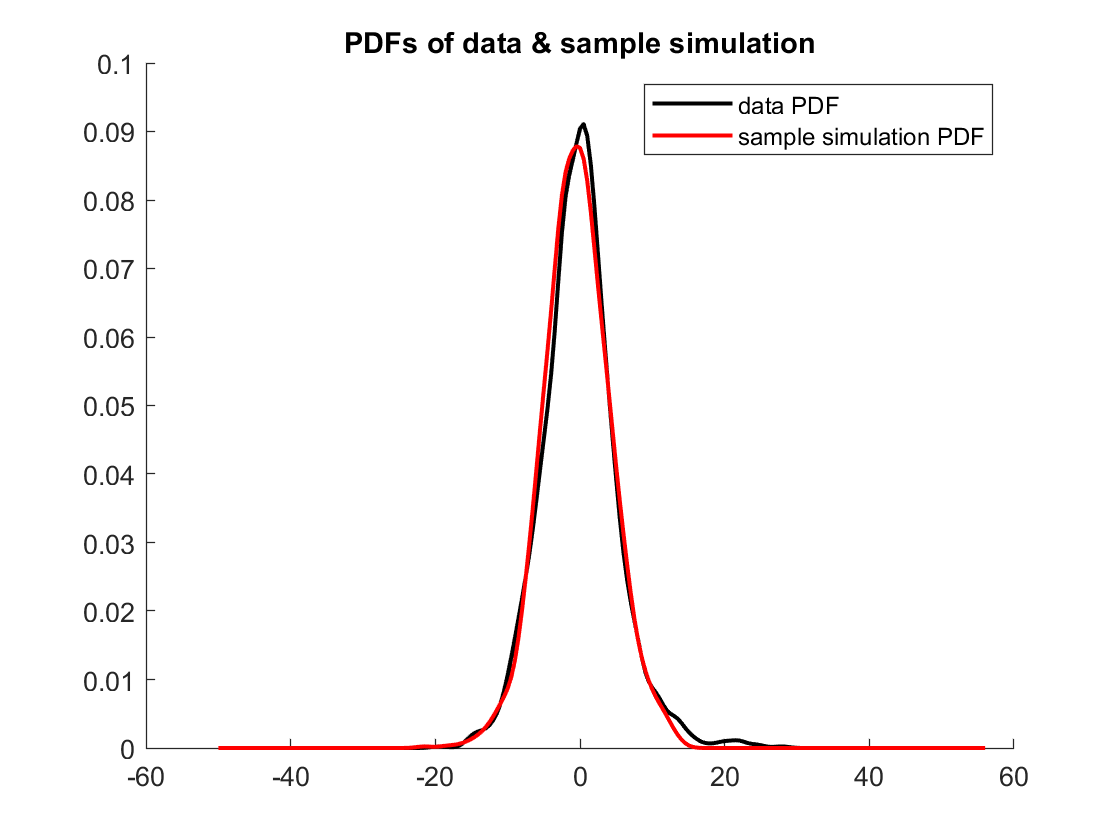

	data summary stats	avgsim summary stats
mean:		-0.016			0.020
std:		5.218			7.517
skew:		0.567			2.443


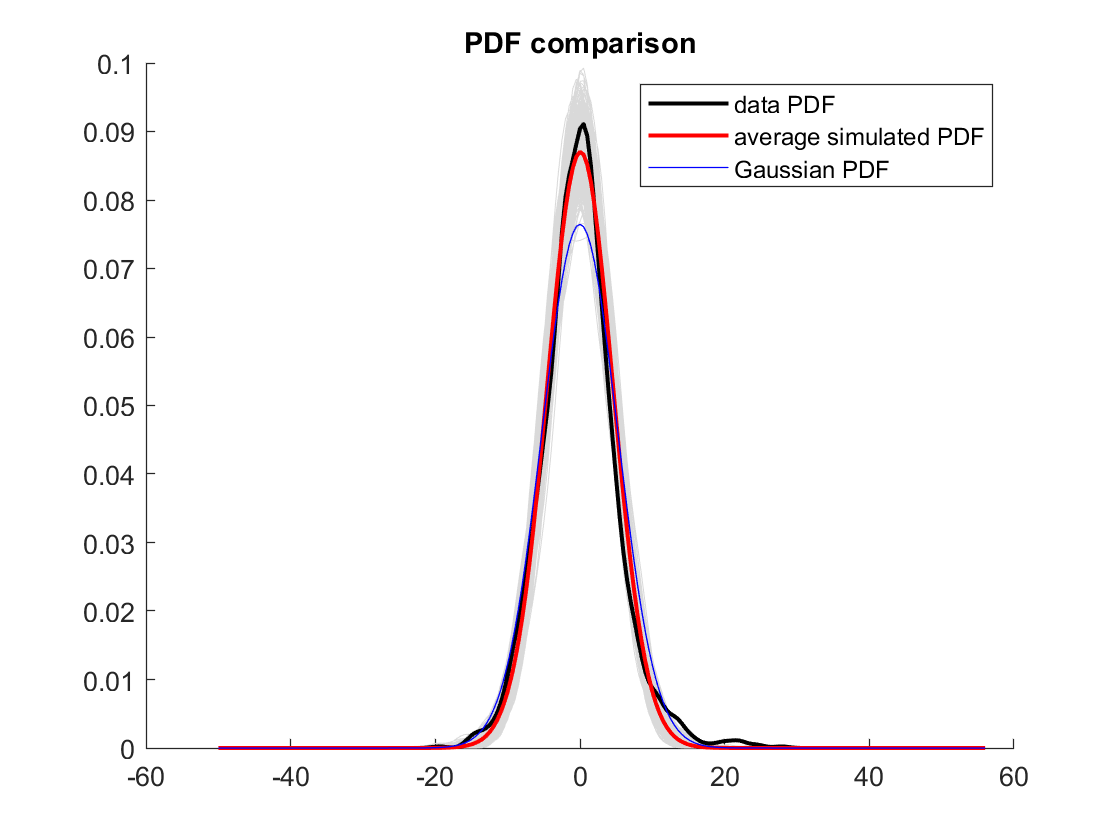

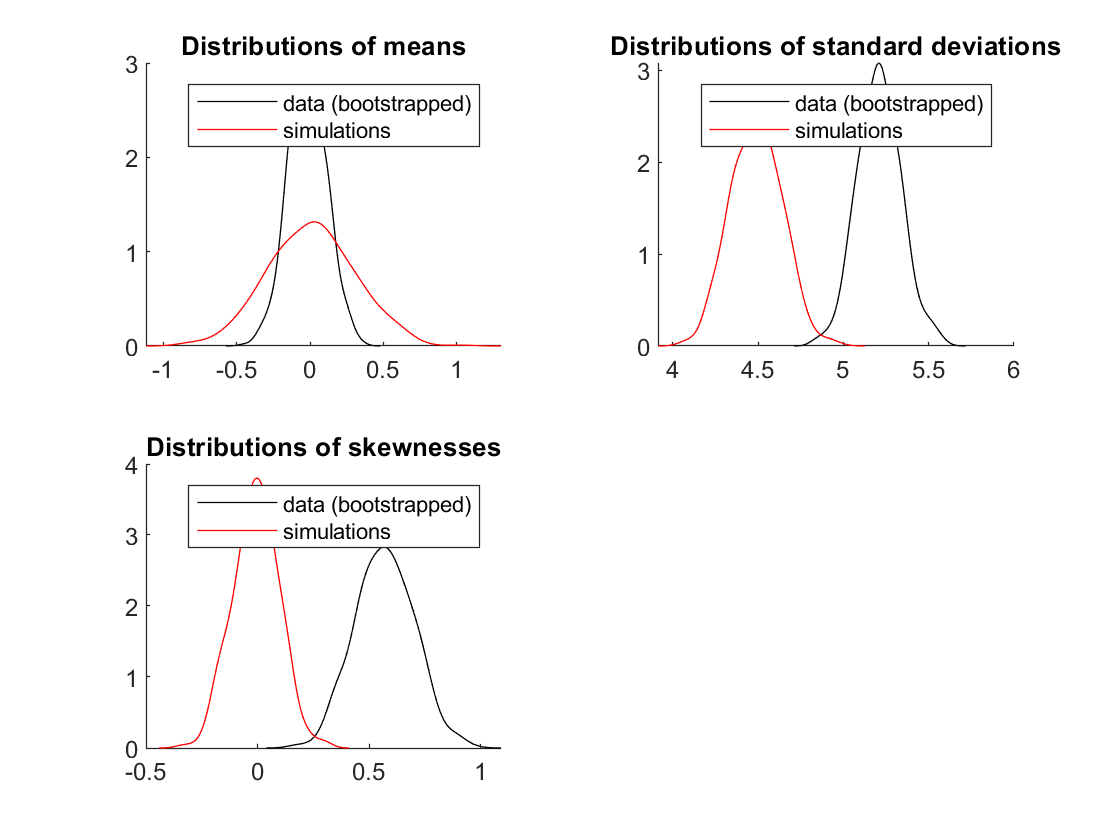

modelpdf_1D(epica_data,Y,M,sim_n_br1D,br_win);

### compare MFTWDFA

[matrix_x,matrix_y,~] = data2matrix(epica_data,Y,M,br_win);
data_x_br1D = reshape(matrix_x',[],1);
data_y_br1D = reshape(matrix_y',[],1);

data_obj_br1D = DataSet("vbl","noise-data",data_x_br1D,data_y_br1D);
sim_obj_br1D = DataSet("vbl","noise-sim",sim_x_br1D,sim_n_br1D);


%{
close all;
% nexttile
hold on;

[t_arr1,f_arr1] = mftwdfa(data_obj_br1D,{"makima",1000,2});
[t_arr2,f_arr2] = mftwdfa(sim_obj_br1D,{"makima",1000,2});

plot(log10(t_arr1),log10(f_arr1),'Color','black');
plot(log10(t_arr2),log10(f_arr2),'Color','red');
%}

### **compare power spectra**

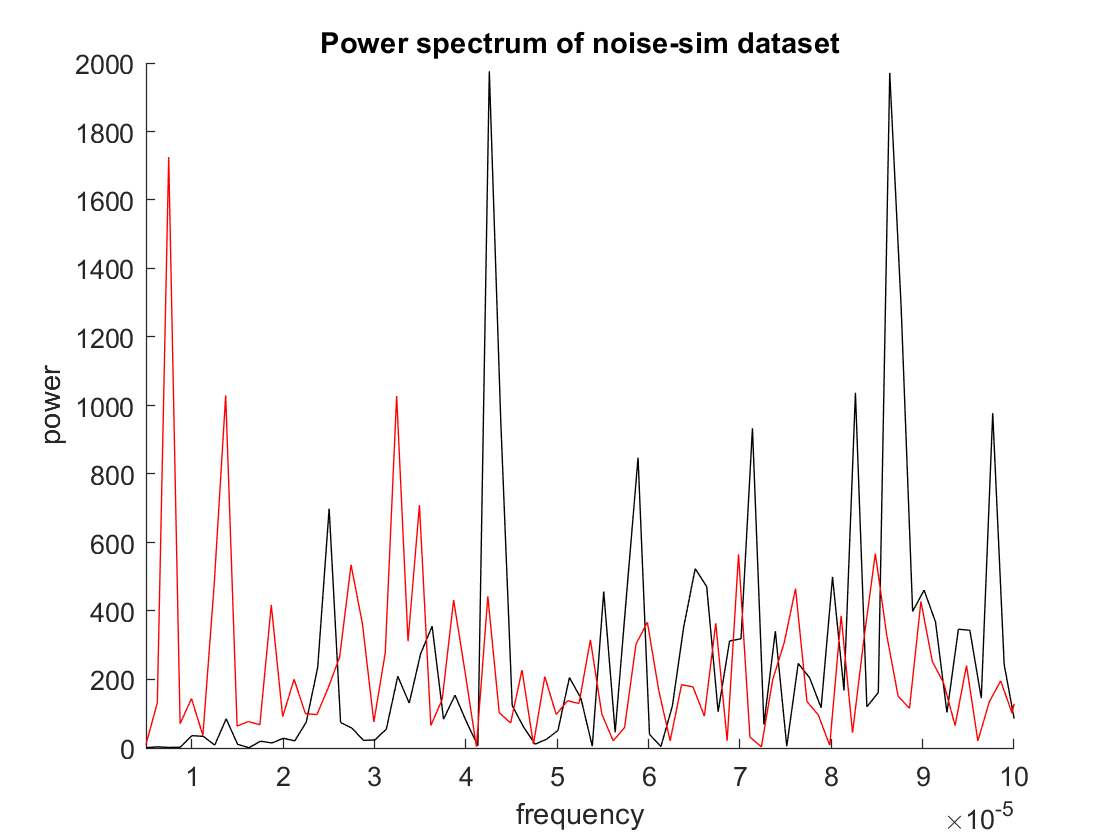

close all;
% nexttile
hold on;
power_spectrum(data_obj_br1D,'black');
power_spectrum(sim_obj_br1D,'red');
xlim([0.000005 0.0001]);

### compare stdev

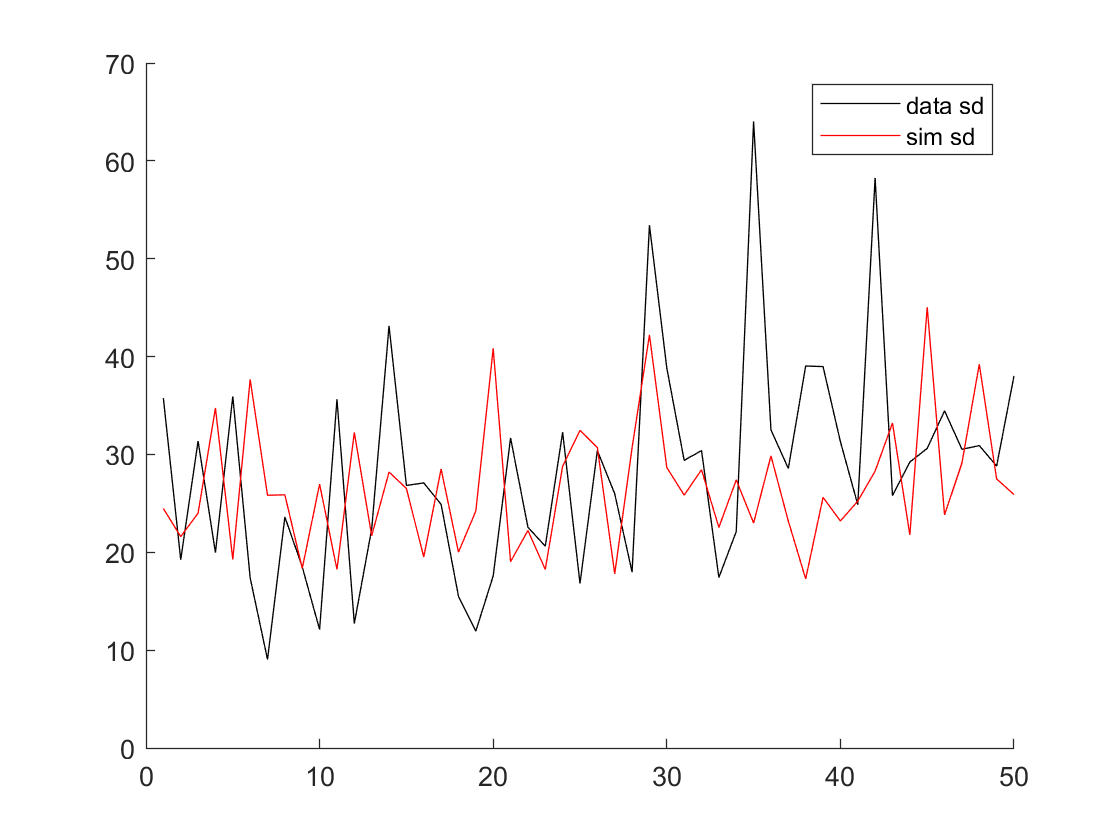

close all;
% monthly std
compare_stdev(data_y_br1D,sim_n_br1D,Y,M);

% compare mean N with data stdev
a_br1D = anf_br1D{1,:};
N_br1D = anf_br1D{2,:};
mean(N_br1D) / sqrt(2 * abs(mean(a_br1D)))

ans = 4.1691

std(data_y_br1D)

ans = 5.2177

# 2D br model

### calculate & simulate

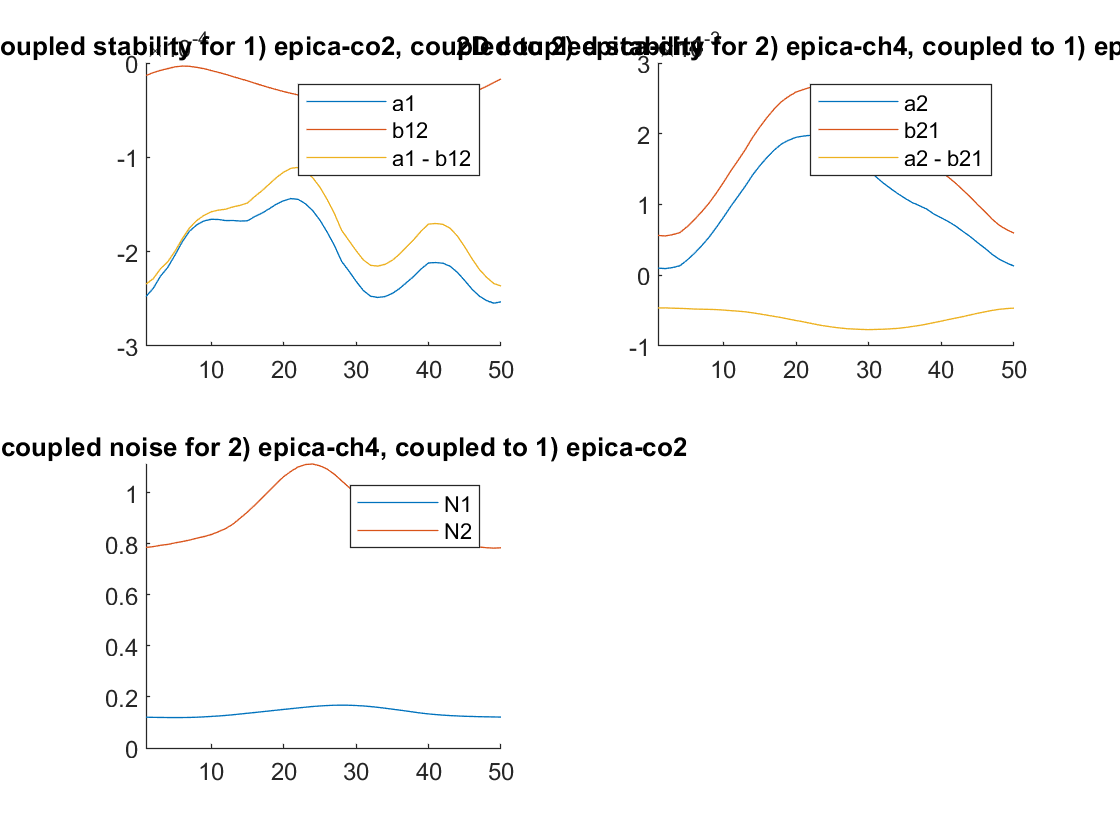

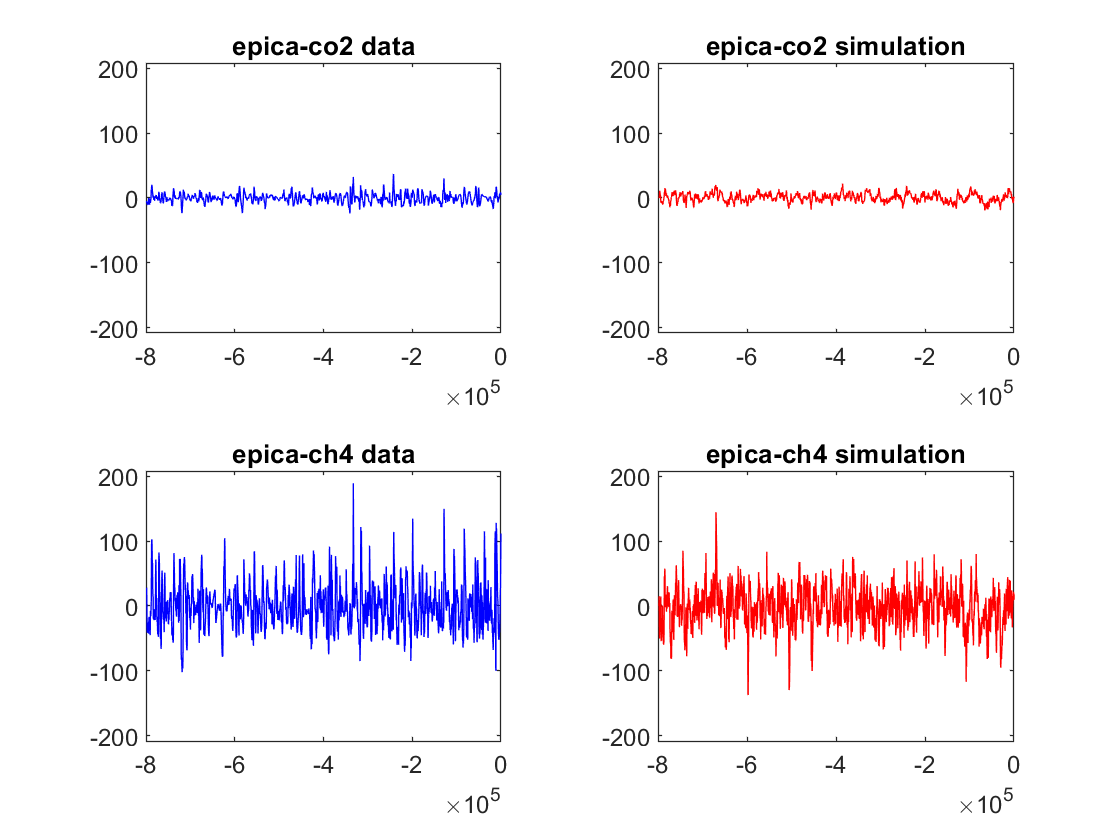

plotting = 1;
br_win = floor(M/2);

% i = 1: CO2
% i = 2: CH4
% i = 3: temp

i1 = 1;
i2 = 2;

close all;

abN_br2D = coupling_2D(obj_arr{i1},obj_arr{i2},Y,M,br_win,plotting);
[~, sim_n1_br2D, sim_n2_br2D] = epica_sim2D(obj_arr{i1},obj_arr{i2},Y,M,abN_br2D,br_win,plotting);

### compare PDFs

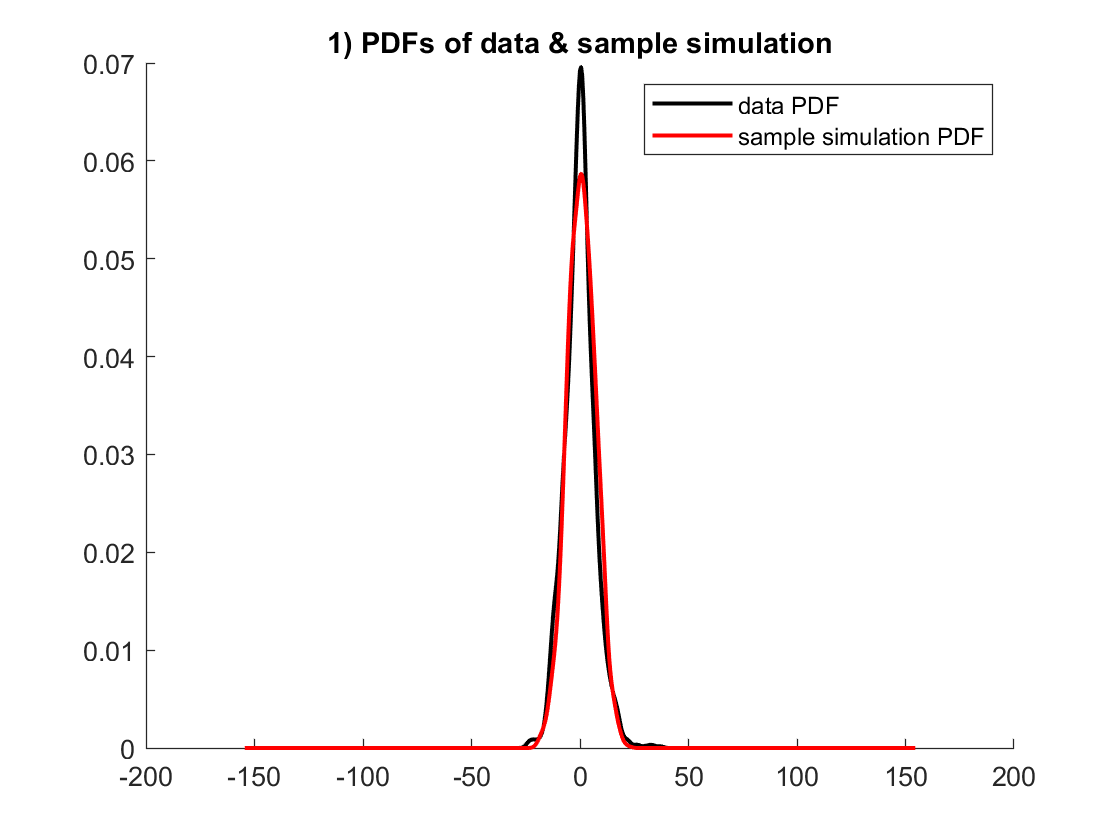

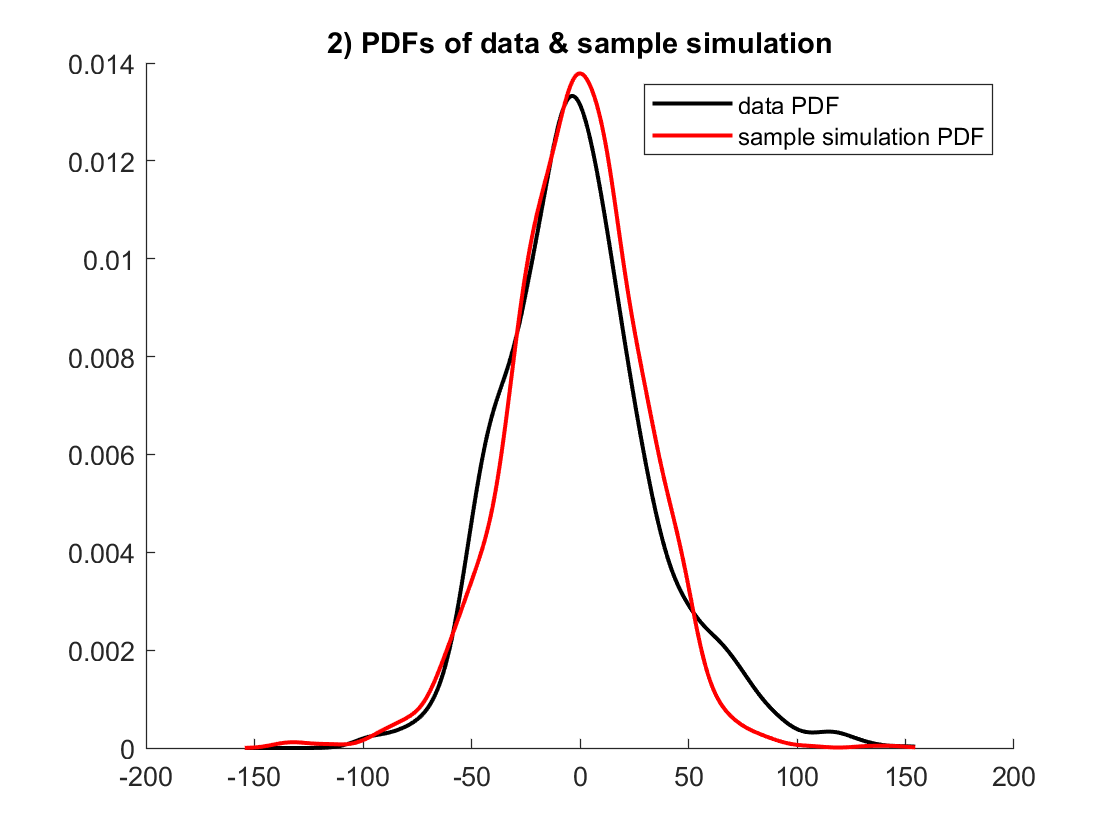

	data (1) summary stats	avgsim summary stats
mean:		-0.003			-0.057
std:		7.005			10.106
skew:		0.321			3.707
	data (2) summary stats	avgsim summary stats
mean:		0.005			-0.043
std:		35.172			50.300
skew:		0.653			3.707


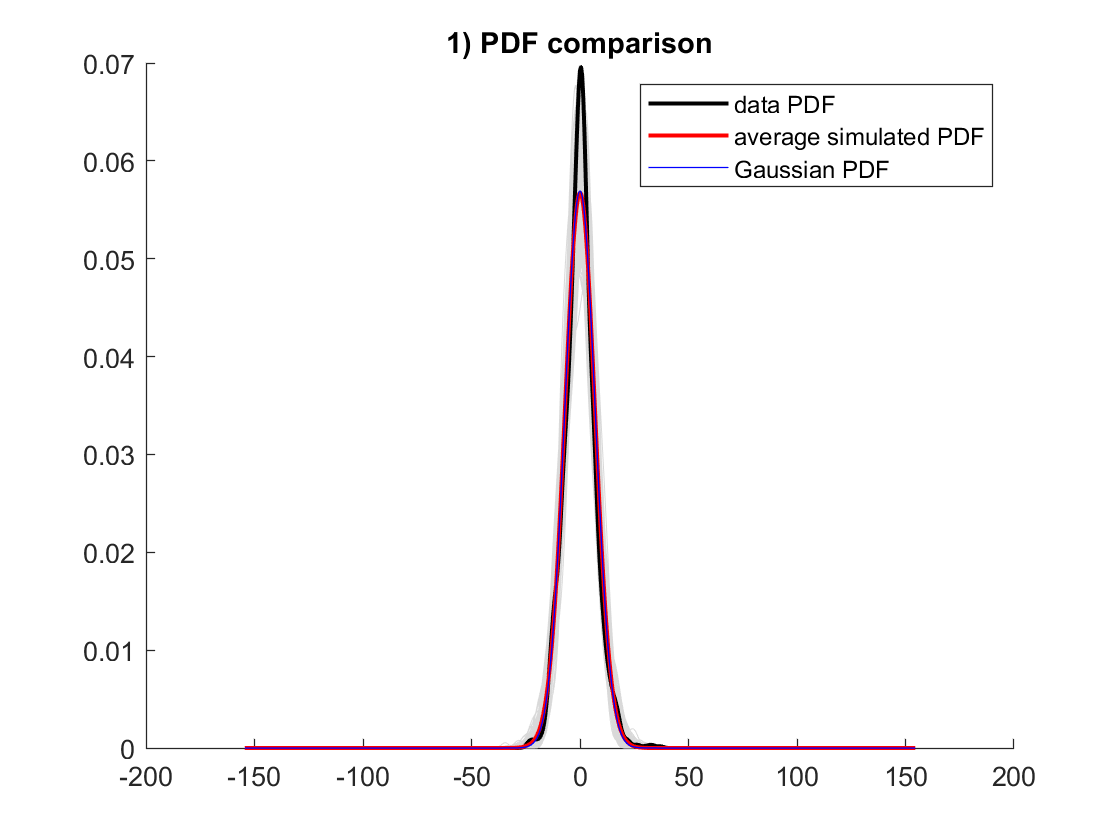

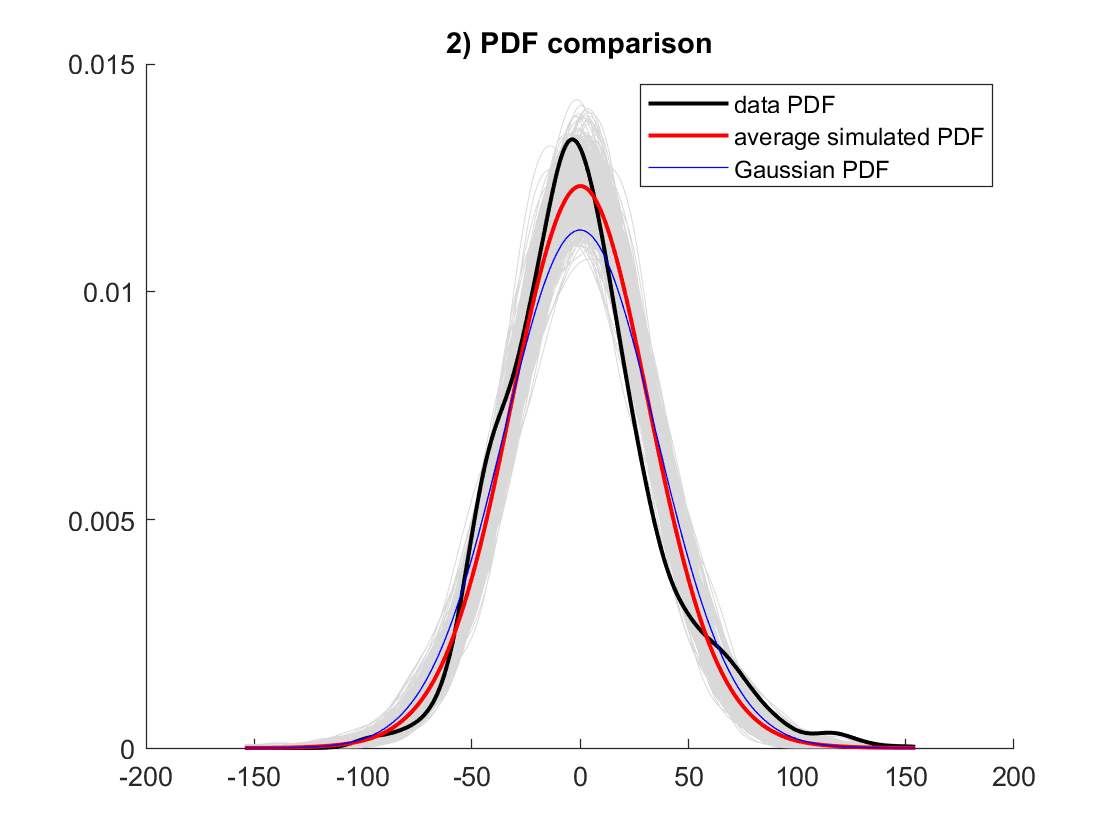

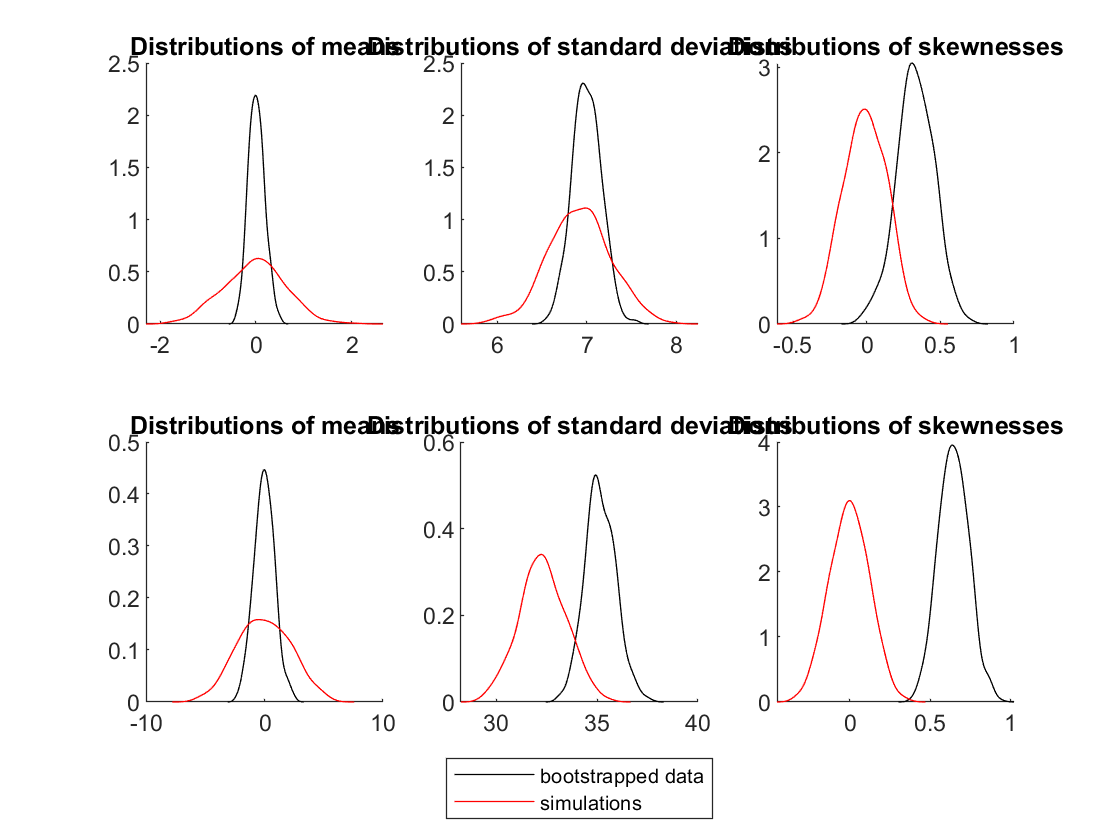

modelpdf_2D(obj_arr{i1},obj_arr{i2},Y,M,sim_n1_br2D,sim_n2_br2D,br_win);

### compare stdev

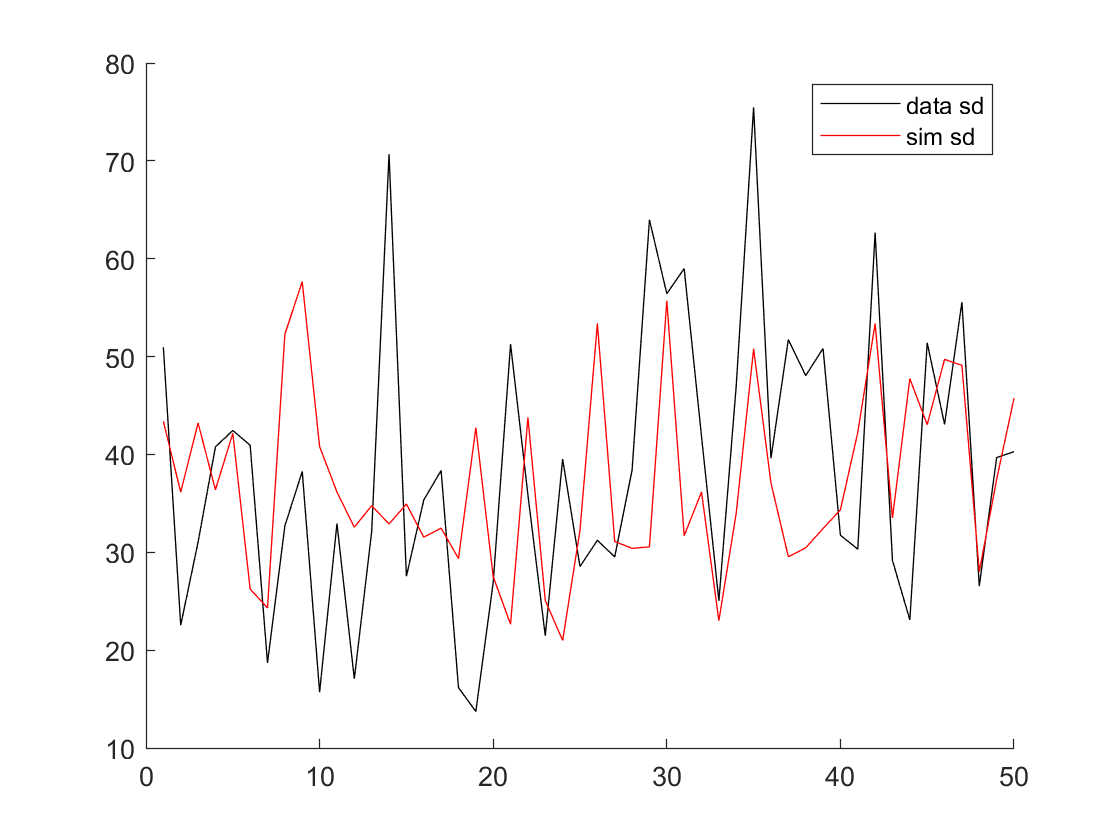

[~,matrix_y1,~] = data2matrix(obj_arr{i1},Y,M,br_win);
[~,matrix_y2,~] = data2matrix(obj_arr{i2},Y,M,br_win);
data_y1_br2D = reshape(matrix_y1',[],1);
data_y2_br2D = reshape(matrix_y2',[],1);

close all;
figure(1);
compare_stdev(data_y1_br2D,sim_n1_br2D,Y,M);

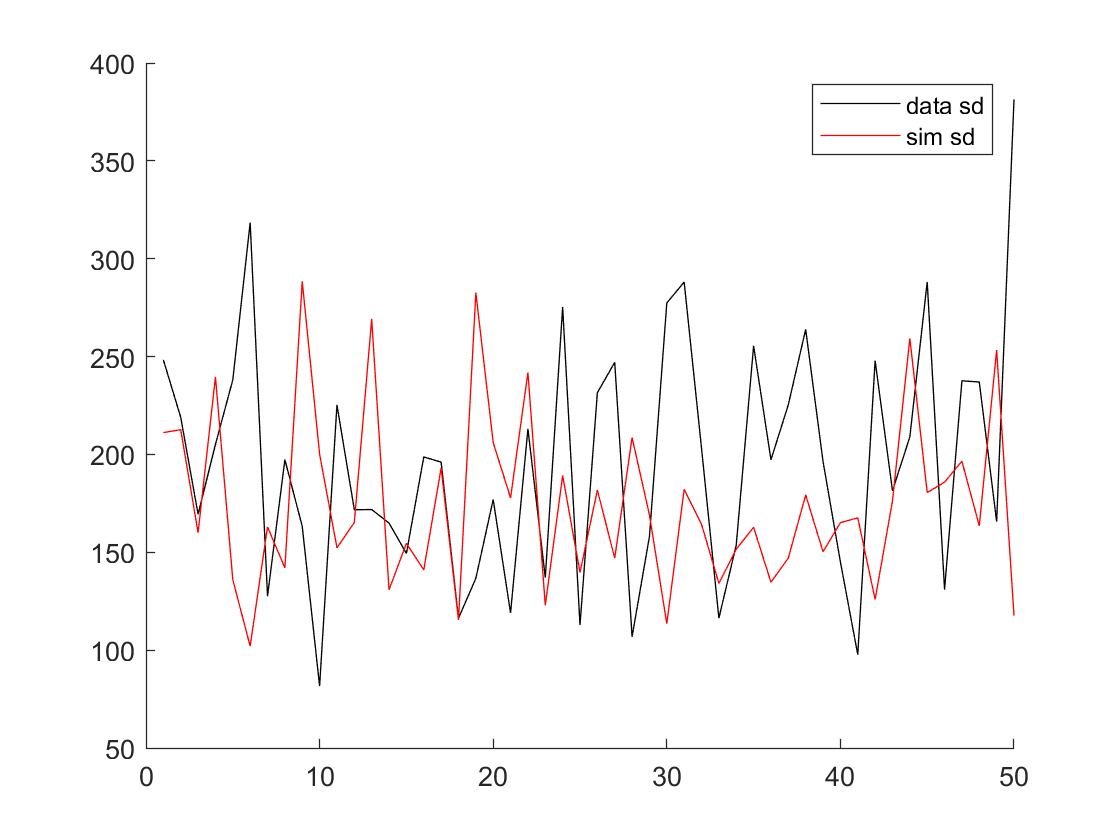

figure(2);
compare_stdev(data_y2_br2D,sim_n2_br2D,Y,M);

# 3D br model

### calculate & simulate

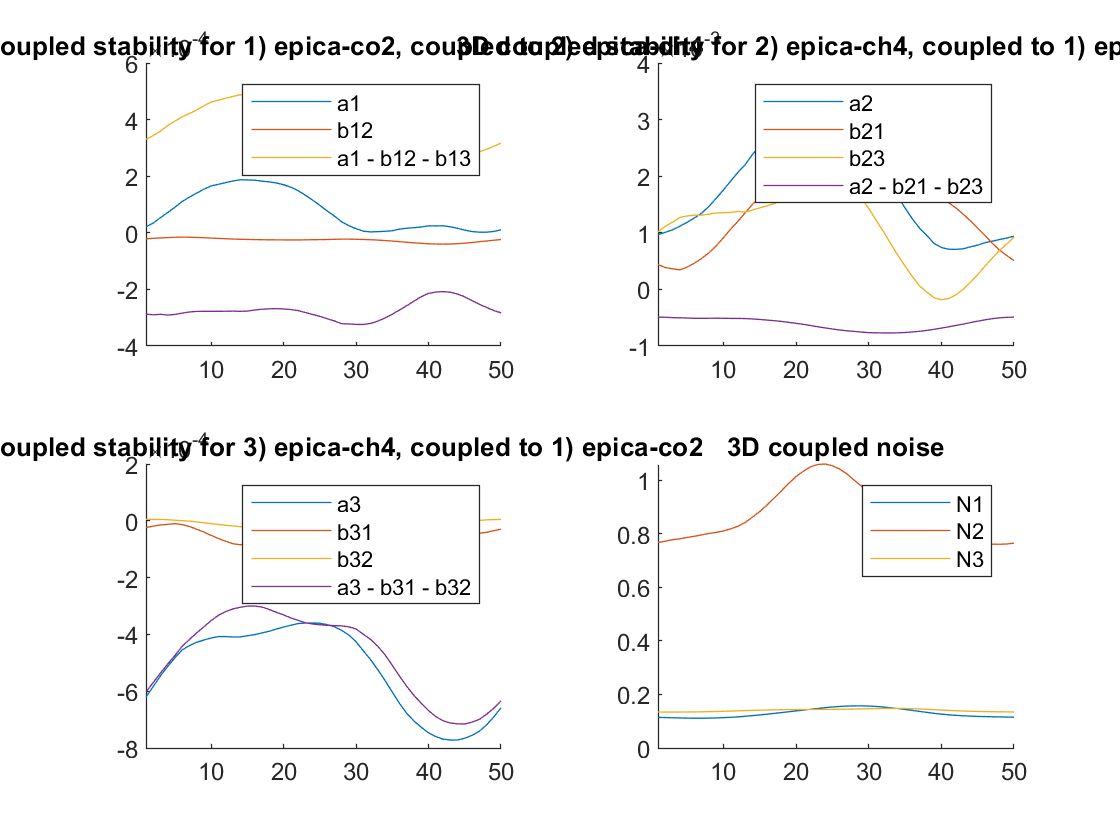

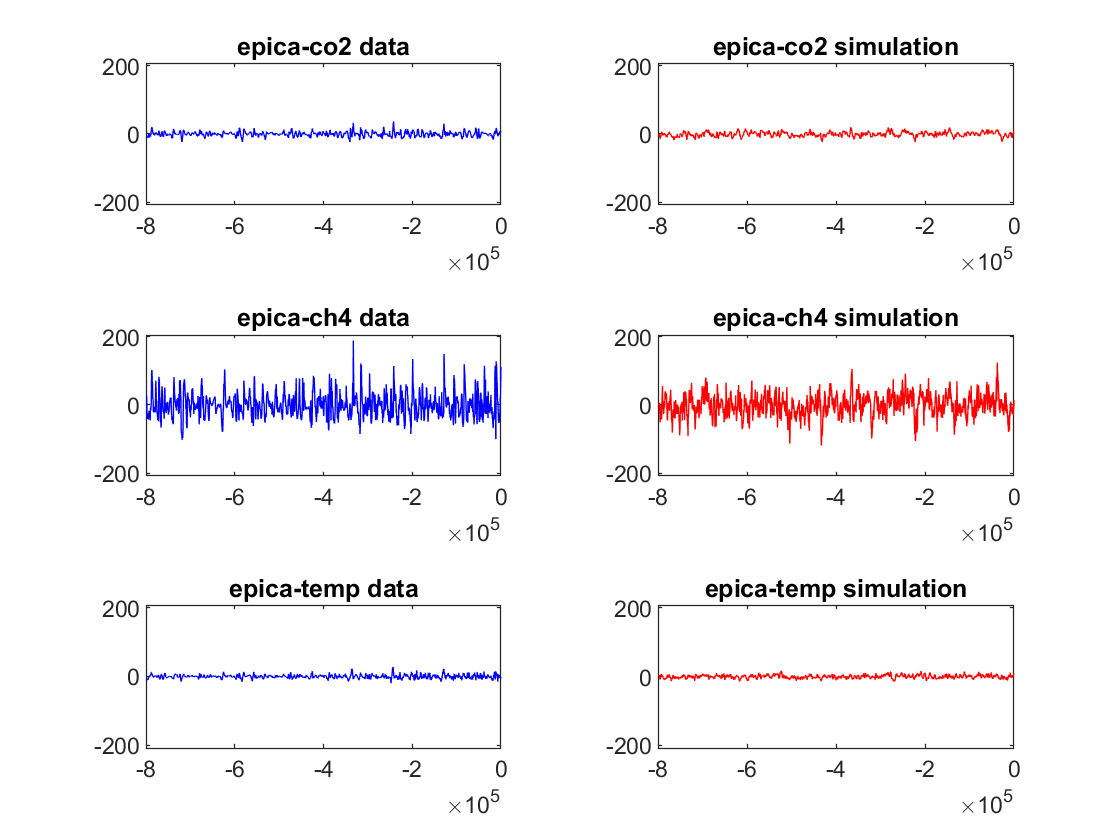

plotting = 1;
br_win = floor(M/2);

% i = 1: CO2
% i = 2: CH4
% i = 3: temp
i1 = 1;
i2 = 2;
i3 = 3;


close all;

abN_br3D = coupling_3D(obj_arr{i1},obj_arr{i2},obj_arr{i3},Y,M,br_win,plotting);
[sim_x_br3D, sim_n1_br3D, sim_n2_br3D, sim_n3_br3D] = epica_sim3D(obj_arr{i1},obj_arr{i2},obj_arr{i3},Y,M,abN_br3D,br_win,plotting);

### compare PDF

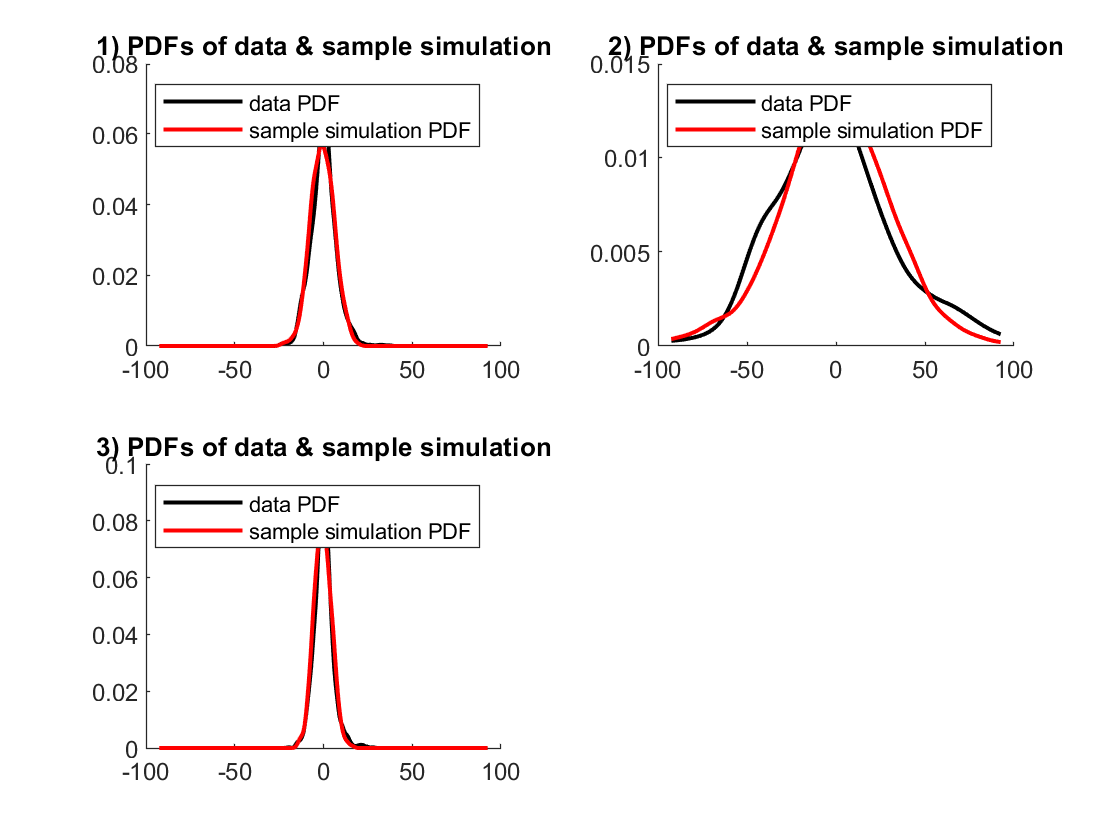

	data (1) summary stats	avgsim summary stats
mean:		-0.003			0.007
std:		7.005			10.106
skew:		0.321			2.814
	data (2) summary stats	avgsim summary stats
mean:		0.005			0.145
std:		35.172			45.922
skew:		0.653			0.408
	data (3) summary stats	avgsim summary stats
mean:		-0.016			-0.008
std:		5.218			7.516
skew:		0.567			3.357


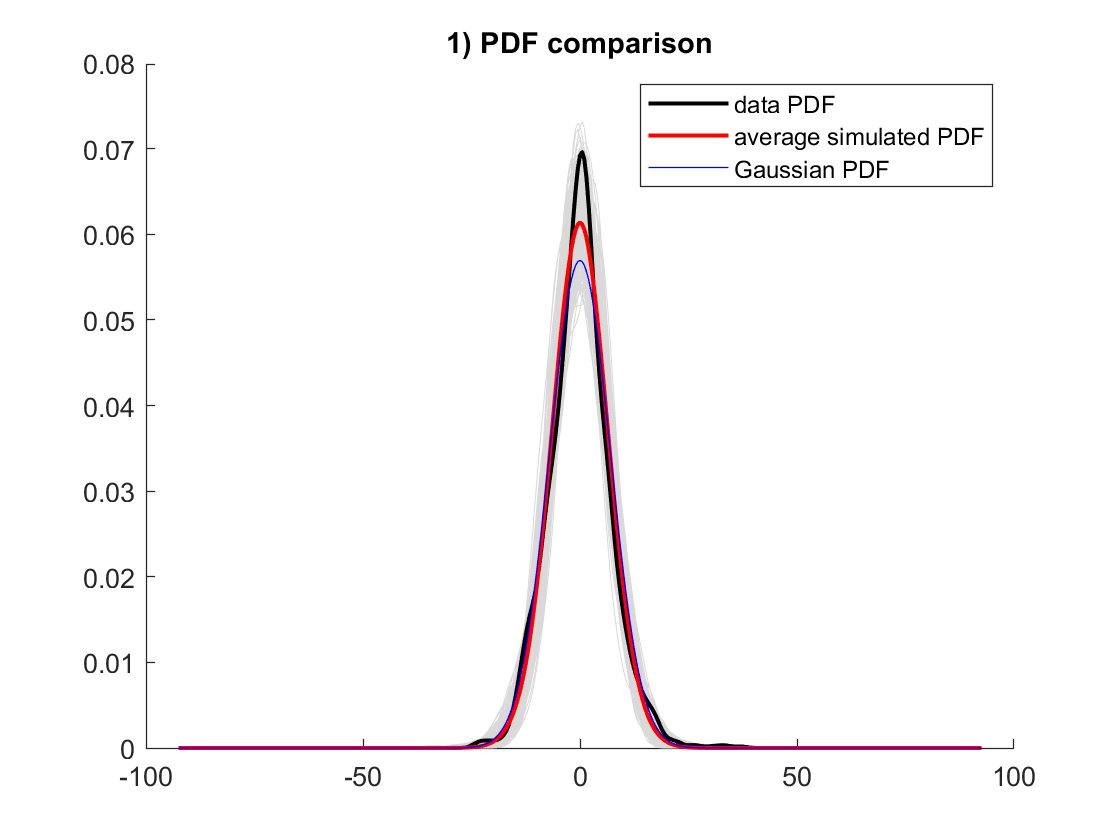

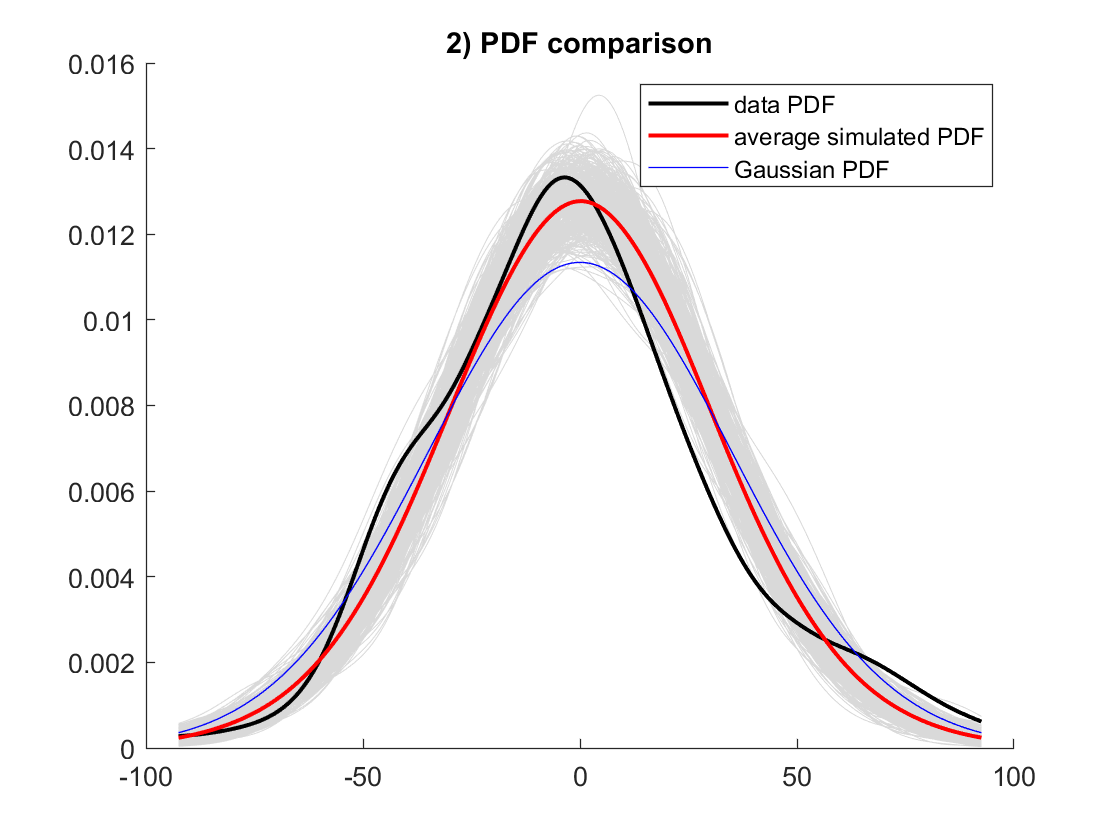

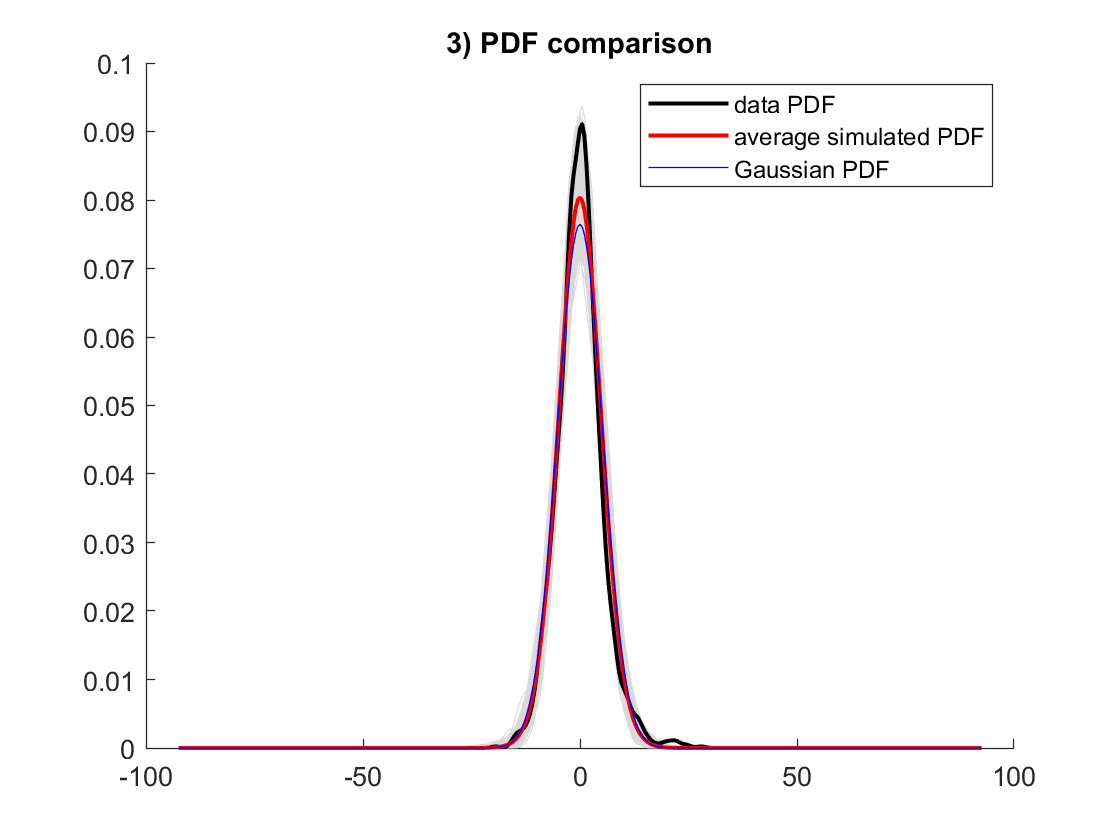

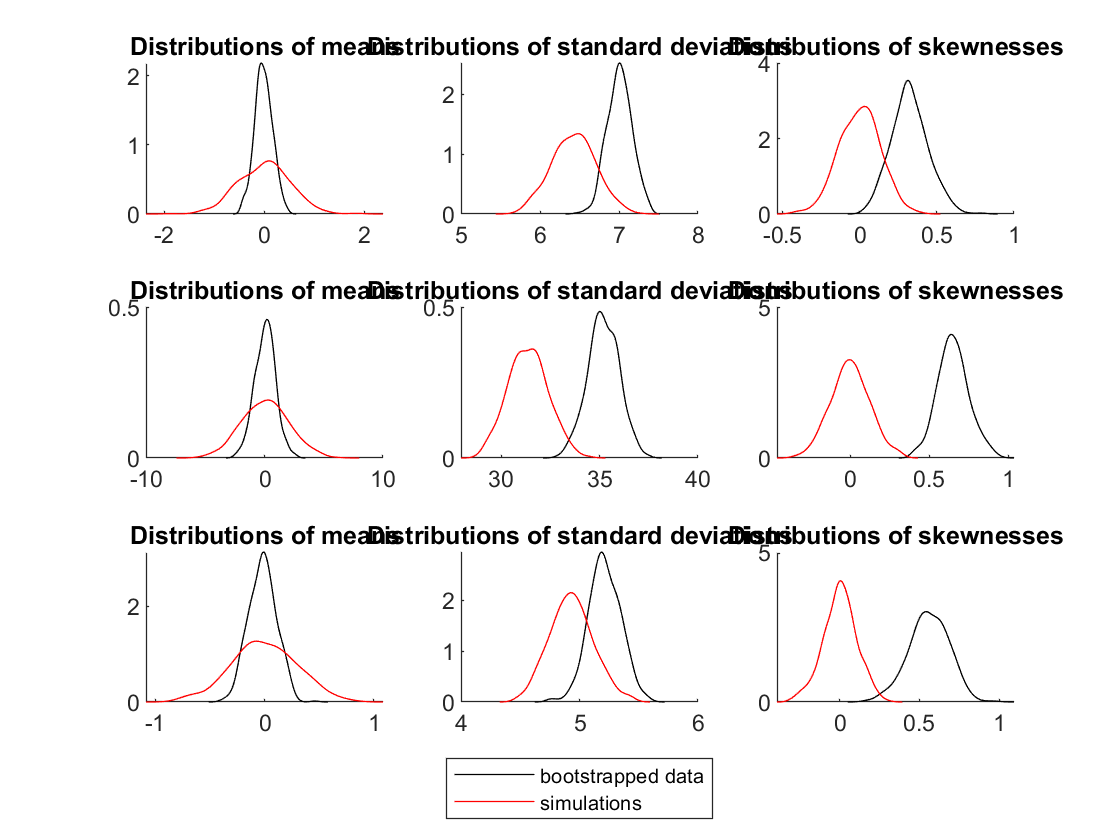

modelpdf_3D(obj_arr{i1},obj_arr{i2},obj_arr{i3},Y,M,sim_n1_br3D,sim_n2_br3D,sim_n3_br3D,br_win);

### compare stdev

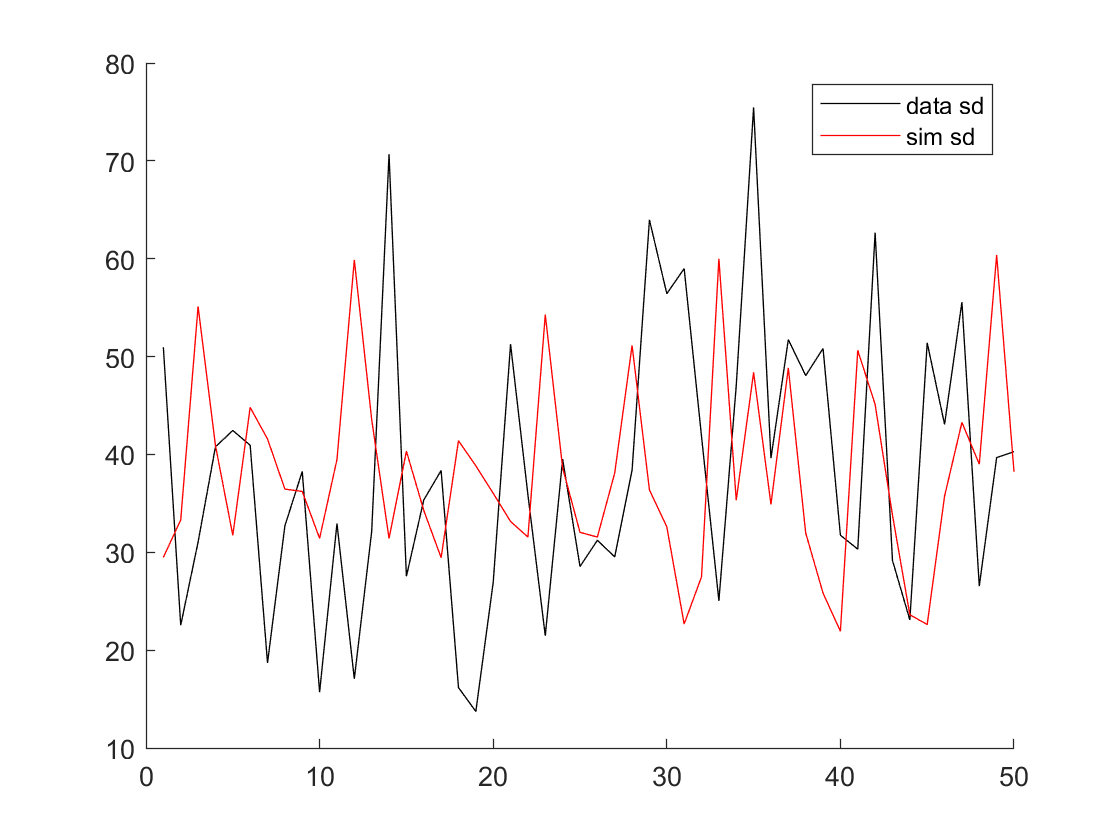

[~,matrix_y1,~] = data2matrix(obj_arr{i1},Y,M,br_win);
[~,matrix_y2,~] = data2matrix(obj_arr{i2},Y,M,br_win);
[~,matrix_y3,~] = data2matrix(obj_arr{i3},Y,M,br_win);
data_y1_br3D = reshape(matrix_y1',[],1);
data_y2_br3D = reshape(matrix_y2',[],1);
data_y3_br3D = reshape(matrix_y3',[],1);

close all;
figure(1);
compare_stdev(data_y1_br3D,sim_n1_br3D,Y,M);

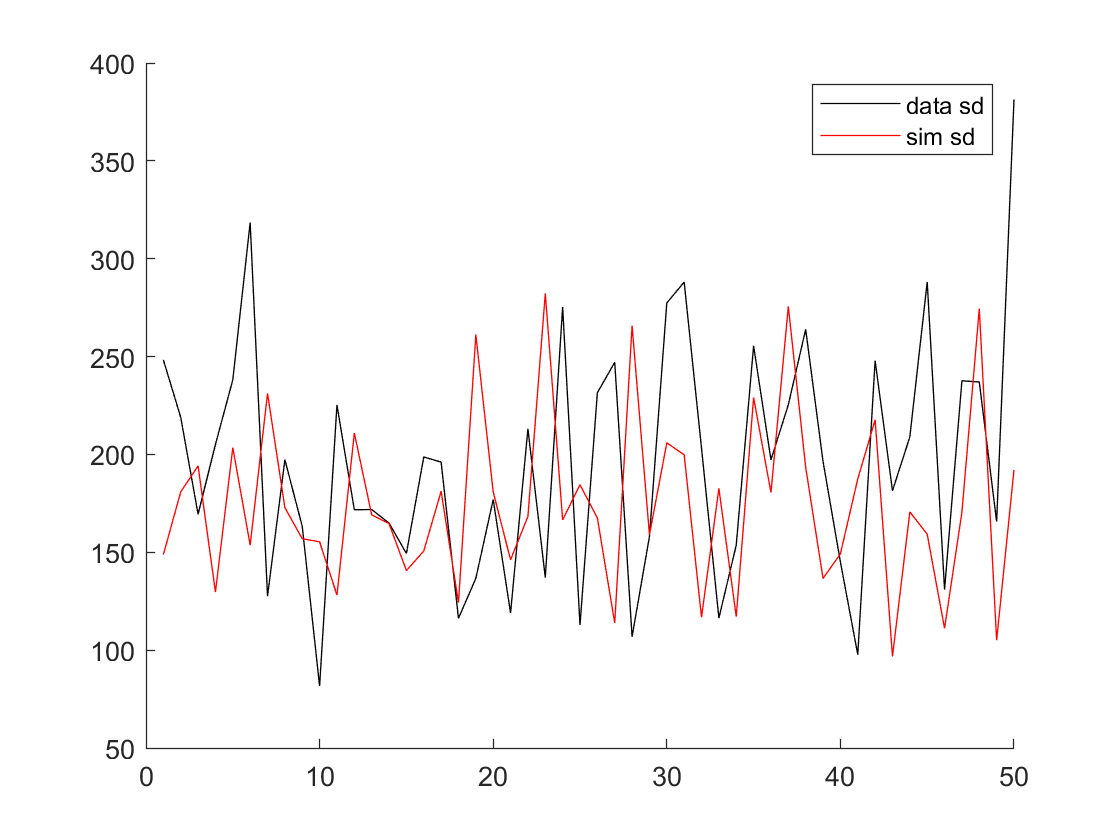

figure(2);
compare_stdev(data_y2_br3D,sim_n2_br3D,Y,M);

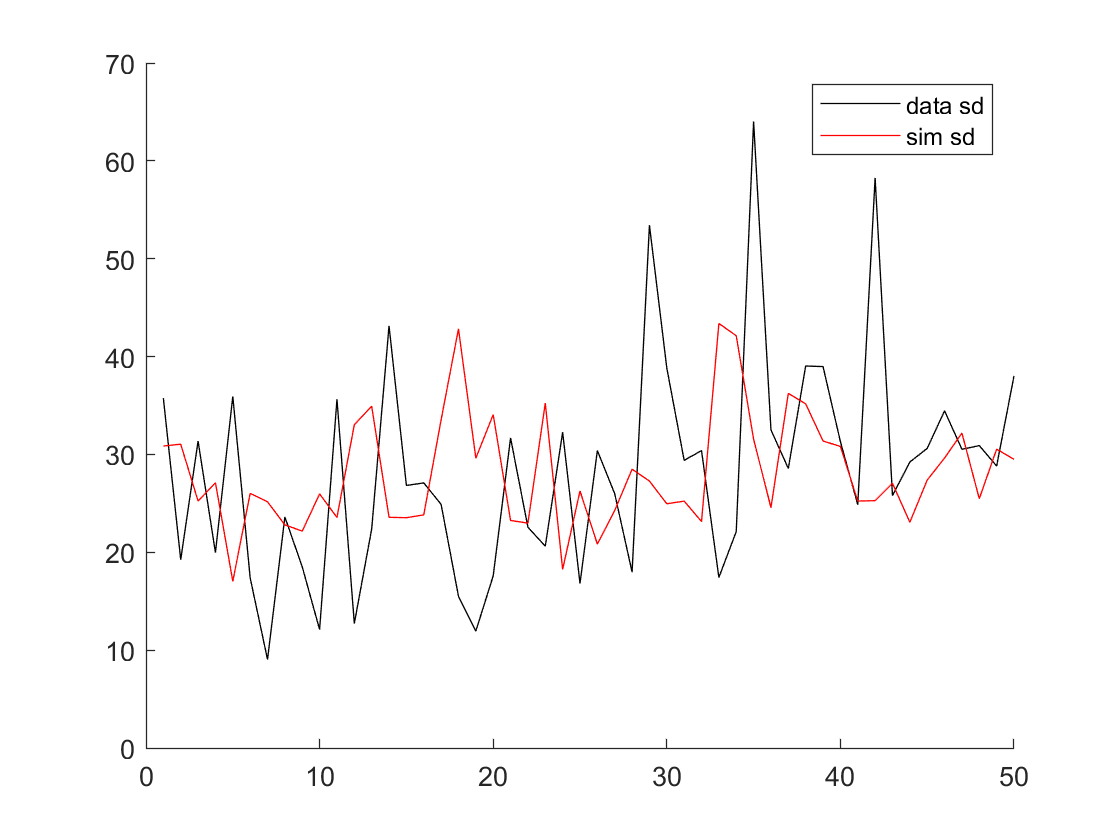

figure(3);
compare_stdev(data_y3_br3D,sim_n3_br3D,Y,M);